# Analyzing various water vapor measurements recorded during the VOCALS-REx flight campaign

Andrew John Buggee

## The VOCALS-REx flight campaign recorded water vapor several different ways

1) Absolute humidity: the mass of water vapor per unit volume of air.

2) Vapor Pressure: the partial pressure of water vapor in a unit volume of air

3) Mixing Ratio: the mass of water vapor per kg of dry air

## Read VOCALS-Rex data

clear variables

%% Define the VOCALS-REx data paths for the machine you're using

% Determine which computer you're using

% Find the folder where the mie calculations are stored
% find the folder where the water cloud files are stored.
if strcmp(whatComputer,'anbu8374')==true

    % -----------------------------------------
    % ------ Folders on my Mac Desktop --------
    % -----------------------------------------

    %     % ***** Define the MODIS Folder *****
    %
    %     modisFolder = ['/Users/anbu8374/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
    %         'MODIS_Cloud_Retrieval/MODIS_data/'];

    % ***** Define the VOCALS-REx File *****

    vocalsRexFolder = ['/Users/anbu8374/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
        'VOCALS_REx/vocals_rex_data/SPS_1/'];

elseif strcmp(whatComputer,'andrewbuggee')==true

    % -------------------------------------
    % ------ Folders on my Macbook --------
    % -------------------------------------

    % ----- Define the MODIS folder name -----

    %     modisFolder = ['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
    %         'MODIS_Cloud_Retrieval/MODIS_data/'];

    % ***** Define the VOCALS-REx Folder *****

    vocalsRexFolder = ['/Users/andrewbuggee/Documents/MATLAB/Matlab-Research/Hyperspectral_Cloud_Retrievals/',...
        'VOCALS_REx/vocals_rex_data/SPS_1/'];

elseif strcmp(whatComputer,'curc')==true

    % ------------------------------------------------
    % ------ Folders on the CU Super Computer --------
    % ------------------------------------------------

    % Define the MODIS folder name

    %     modisFolder = '/projects/anbu8374/MODIS_data/';

    % ***** Define the VOCALS-REx Folder *****

    vocalsRexFolder = '/projects/anbu8374/VOCALS_REx_data/';


end


% *** Read VOCALS-REx data file ***

% ----- November 9 data -----
% vocalsRexFile = 'RF11.20081109.125700_213600.PNI.nc';

% ----- November 11 data -----
vocalsRexFile = 'RF12.20081111.125000_214500.PNI.nc';


vocalsRex = readVocalsRex([vocalsRexFolder,vocalsRexFile]);



## Convert Absolute Humidity to Number Concentration

$N_c = q' \, \frac{N_a}{M}$   where $q'$ is the absolute humidity, $N_a$ is Avogadro's number and $M$ is the molar mass of water

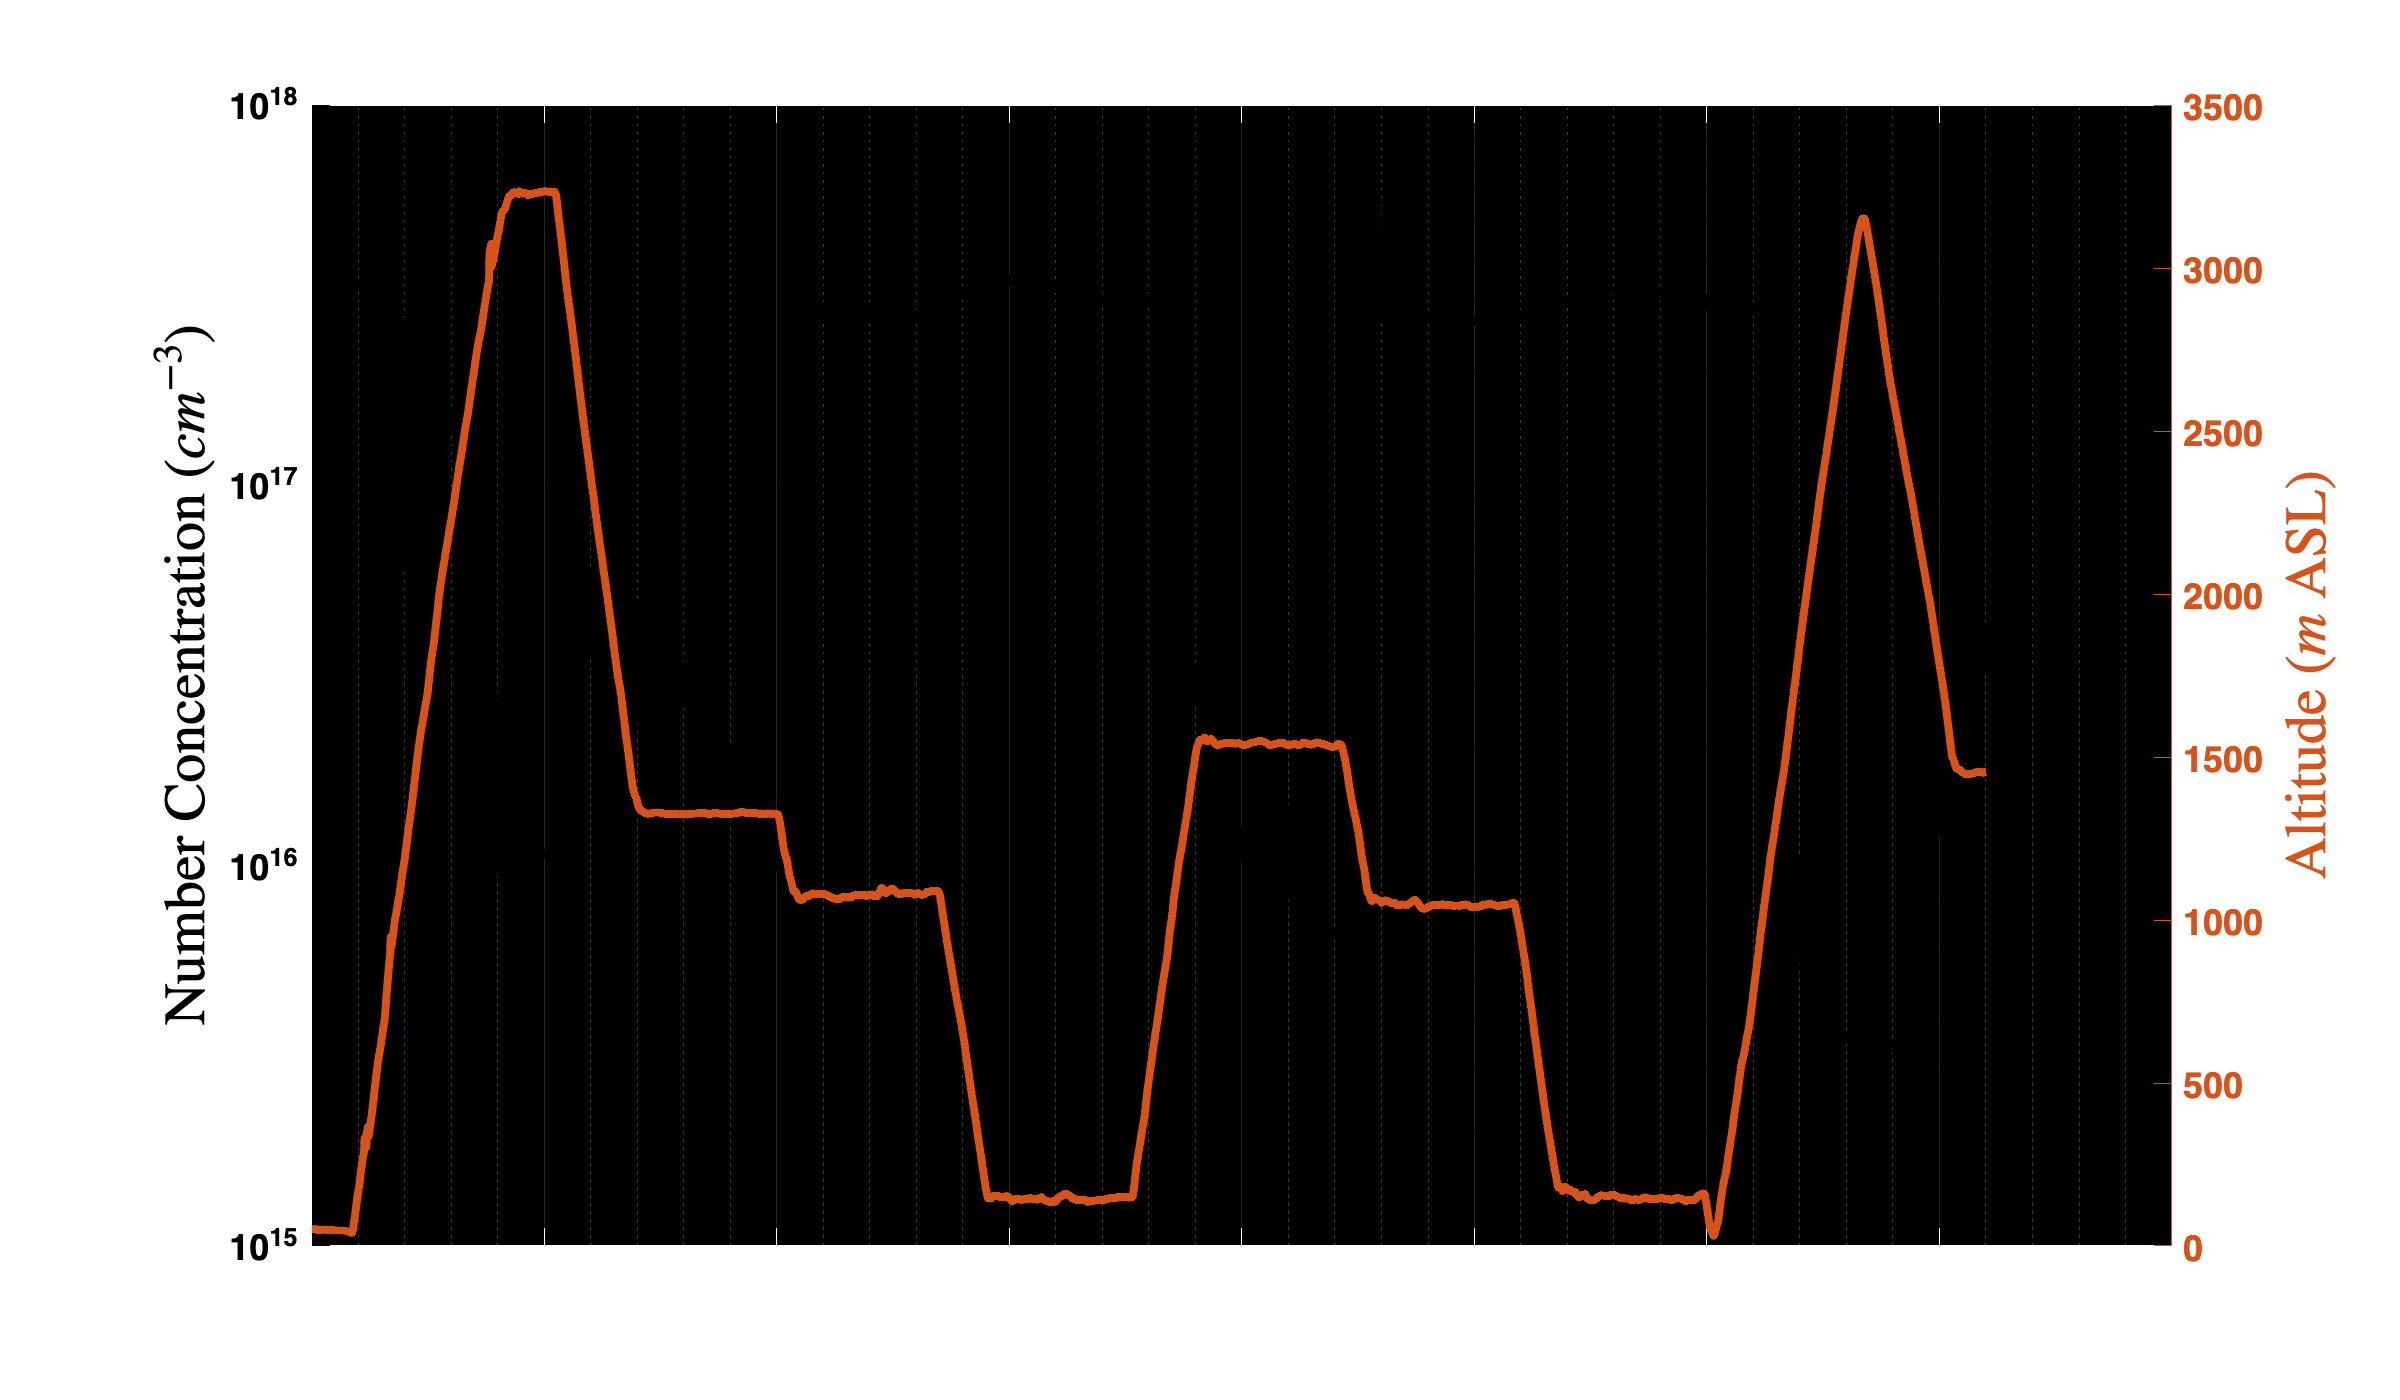

% open physical constants library
con = physical_constants;



% compute number concentration from absolute humidity
Nc_vapor = vocalsRex.absolute_humidity .* (con.N_A/(con.Mol_mass_h20_vap*1e3));       % # of molecules/m^3

% convert units to inverse cubic cm
Nc_vapor = Nc_vapor ./ 1e6;                                                 % # of molecules/cm^3

% try computing number concentration from the partial pressure as well
Nc_vapor_pp = (vocalsRex.vapor_pressure.*1e2) .* (con.N_A./(con.R_uni * (vocalsRex.temp + 273.15)));     % # of molecules / m^3

% convert units to inverse cubic cm
Nc_vapor_pp = Nc_vapor_pp ./ 1e6;                                                 % # of molecules/cm^3

% Let's plot the first 2 hours of water vapor measurements versus time, along with altitude
idx_time = (vocalsRex.time<7200);
figure;
semilogy(vocalsRex.time(idx_time), Nc_vapor(idx_time), 'k')
xlabel('Time since takeoff ($hrs$)', 'Interpreter','latex')
ylabel('Number Concentration ($cm^{-3}$)', 'Interpreter','latex', 'FontSize',15)
title('Water Vapor Concentration', 'Interpreter','latex')
hold on;
yyaxis right
plot(vocalsRex.time(idx_time), vocalsRex.altitude(idx_time))
grid on; grid minor
ylabel('Altitude ($m$ ASL)', 'Interpreter','latex')
set(gcf, 'Position', [0 0 1200 700])

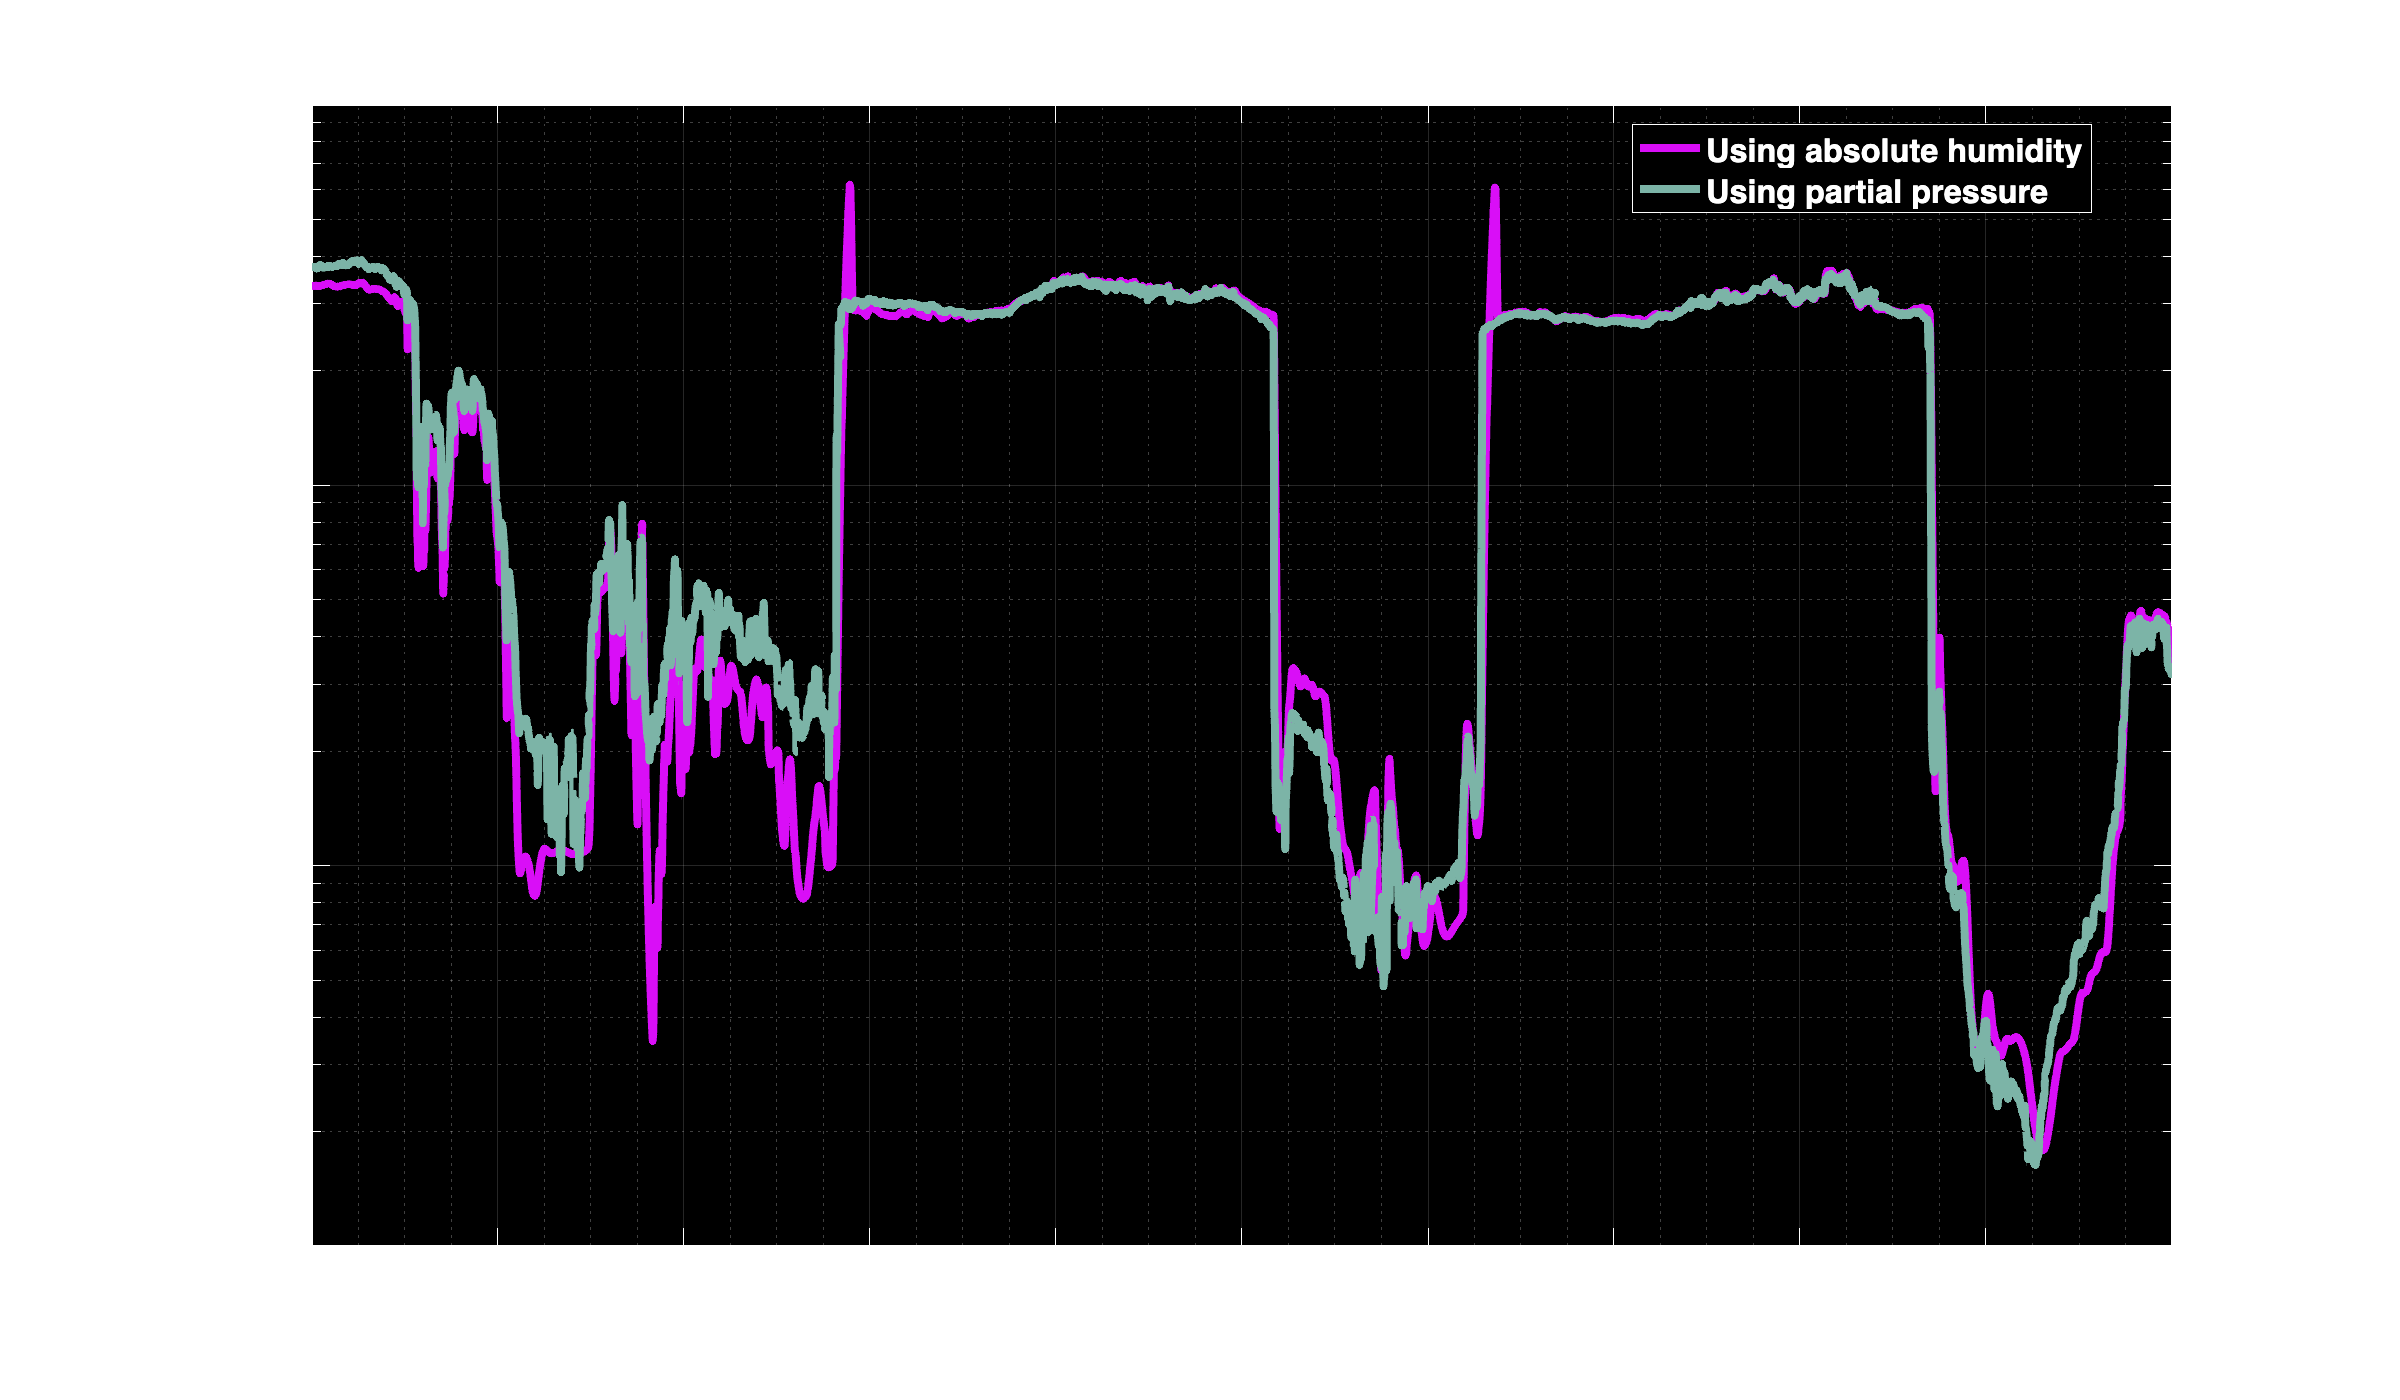




% Let's compare the two calculations of water vapor concentration
idx_time = (vocalsRex.time<7200);
figure;
semilogy(vocalsRex.time(idx_time)./3600, Nc_vapor(idx_time), 'color', mySavedColors(1, 'fixed'))
xlabel('Time since takeoff ($hrs$)', 'Interpreter','latex')
ylabel('Number Concentration ($cm^{-3}$)', 'Interpreter','latex')
title('Water Vapor Concentration', 'Interpreter','latex')
hold on;
semilogy(vocalsRex.time(idx_time)./3600, Nc_vapor_pp(idx_time), 'color', mySavedColors(2, 'fixed'))
grid on; grid minor
legend('Using absolute humidity', 'Using partial pressure', 'location', 'best')
set(gcf, 'Position', [0 0 1200 700])

Interesting. I don't like the anomolous spikes in number concetration that exceed the surface values when using absolute humidity. So perhaps I should trust the calculation using partial pressure more.

## Find Vertical Profiles of Clouds

Let's find all vertical profiles where the plane started below cloud and flew above, sampling along the vertical dimension

% ----- Find all vertical profiles within VOCALS-REx data ------
% find all vertical profiles in the vocals-REx data set. Vertical profiles
% qualify if the total number concentration is above 10^0 and relatively
% flat, the plane is climbing in altitude, and clears the cloud deck from
% bottom to top. If this is all true, save the vocals rex data
lwc_threshold = 0.03;           % g/m^3
stop_at_max_lwc = false;         % truncate profile after the maximum lwc value
Nc_threshold = 25;               % # droplets/cm^3


% Lets only keep the vocalsRex data we need
% Time is measured in seconds since the startTime


% ----- Find all vertical profiles within VOCALS-REx data ------
tic
vert_prof = find_verticalProfiles_VOCALS_REx_ver2(vocalsRex, lwc_threshold, stop_at_max_lwc, Nc_threshold);toc

Elapsed time is 49.413473 seconds.


toc

Elapsed time is 49.423449 seconds.


## Plot a single example of water vapor concentration below, within and above cloud

Let's plot segments of the vocalsRex flight path showing total number concentration, liquid water content, effective radius and water vapor concentration

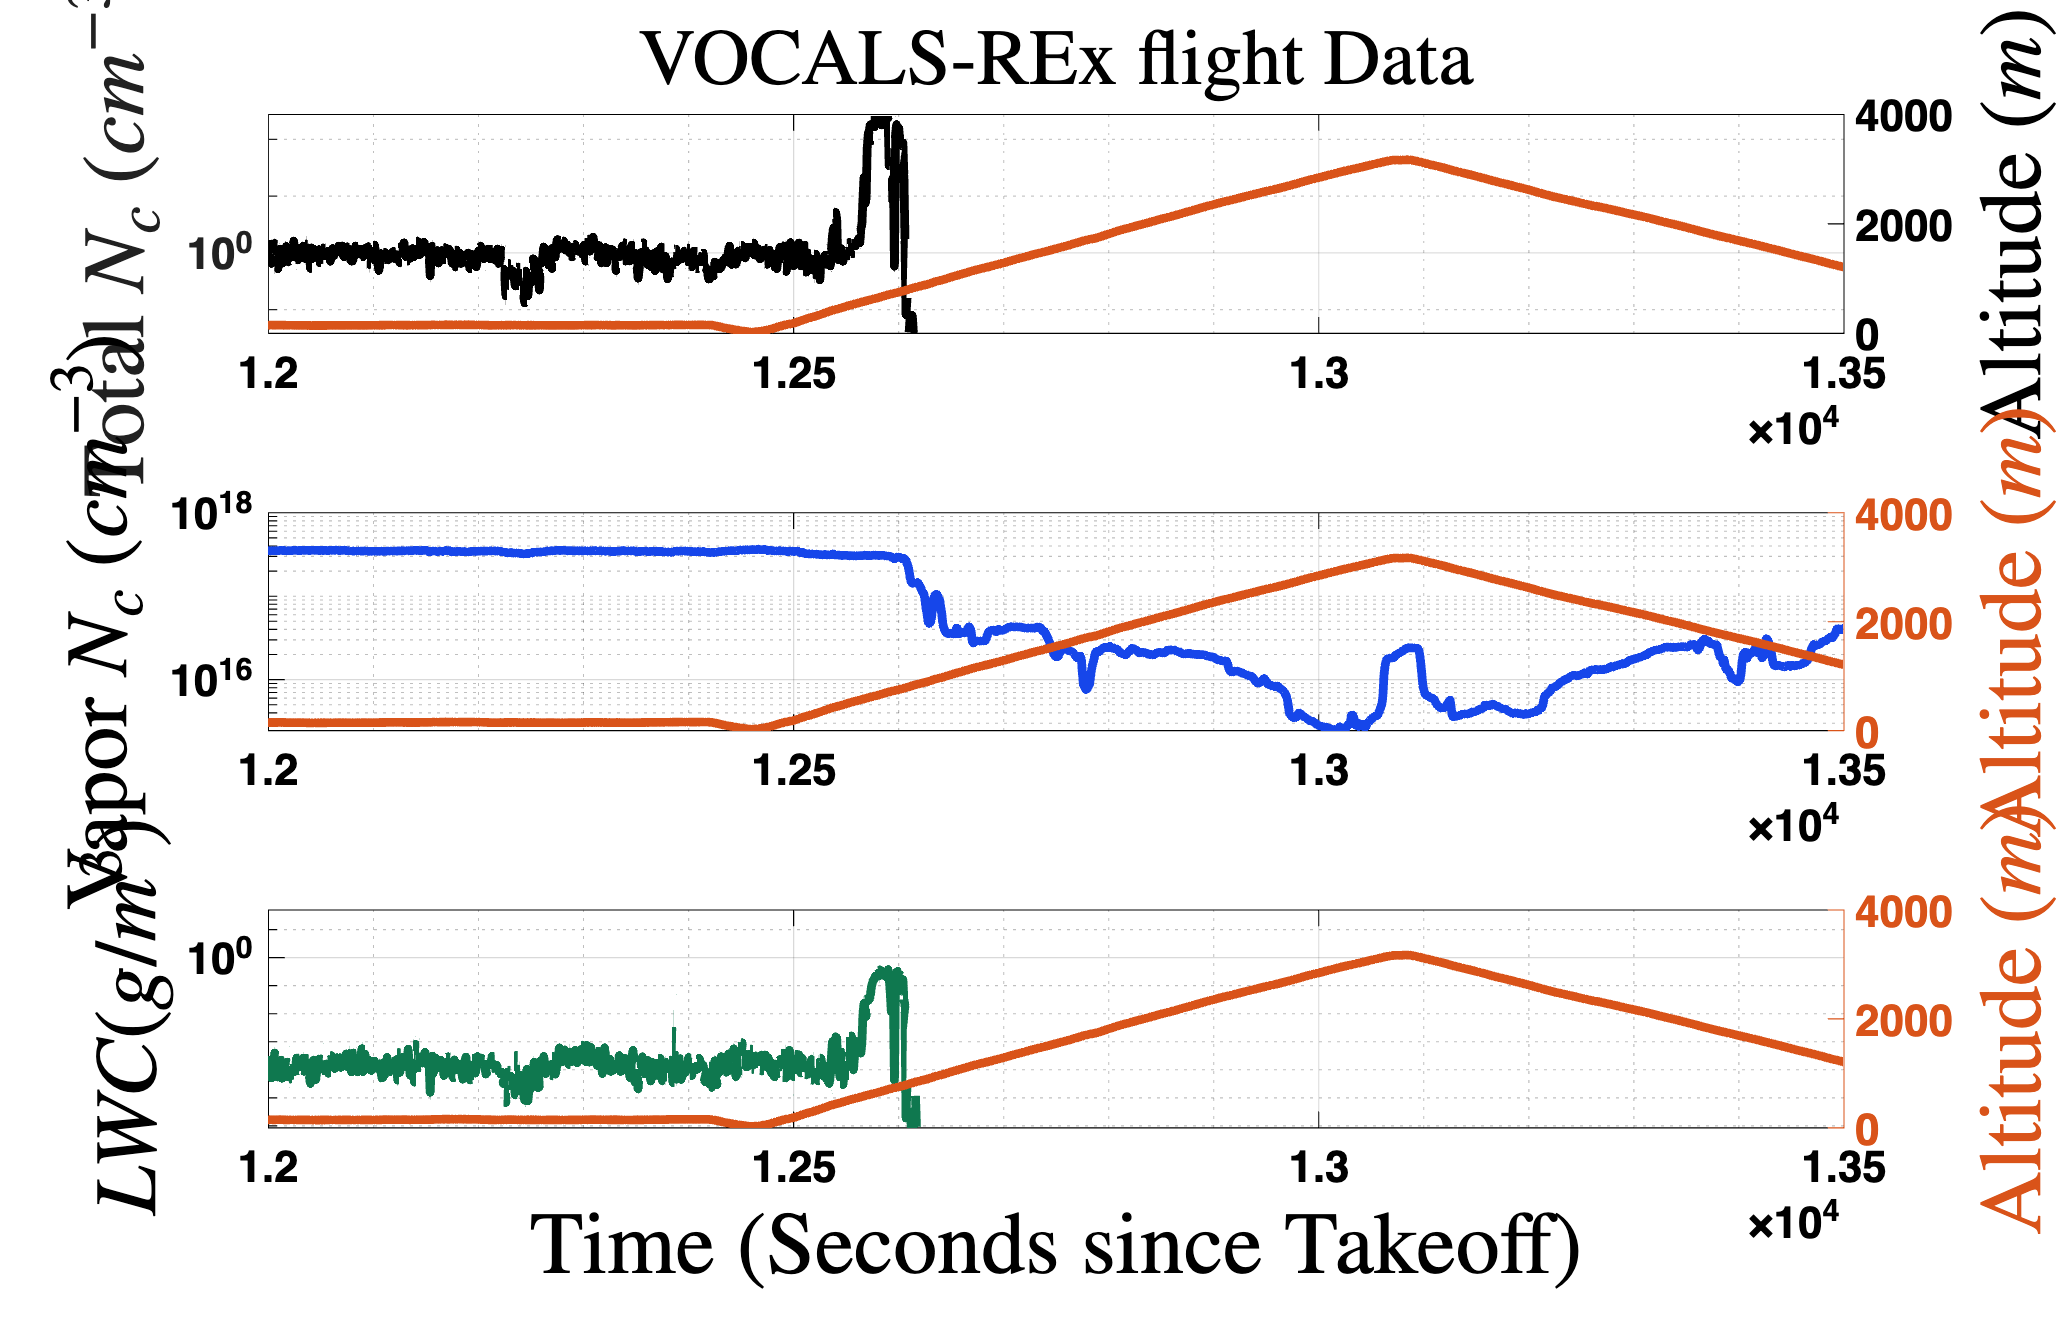

fnt_size_ylabel = 15;

%  Below this, create a subplot with effective radius versus time and
%  altitude versus time


figure; subplot(3,1,1)
semilogy(double(vocalsRex.time), vocalsRex.total_Nc, 'Color','k');
grid on; grid minor;
ylabel('Total $N_c$  $(cm^{-3})$','Interpreter','latex', 'Color','k', 'FontSize', fnt_size_ylabel)
title('VOCALS-REx flight Data', 'Interpreter','latex')

hold on;
yyaxis right;
plot(double(vocalsRex.time), vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex', 'FontSize', fnt_size_ylabel)

% grab current axes
ax1 = gca;

s2 = subplot(3,1,2);
semilogy(double(vocalsRex.time), vocalsRex.Nc_vapor_partPres, 'Color', mySavedColors(18, 'fixed'));
set(s2,'YColor', mySavedColors(18, 'fixed'));
grid on; grid minor;
%ylim([0, 50])           % no need to look at effective radii larger than 50 microns

hold on;
yyaxis right;
plot(double(vocalsRex.time), vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex', 'FontSize', fnt_size_ylabel)

% change color of left y axis
yyaxis left
ylabel('Vapor $N_c$ $(cm^{-3})$','Interpreter','latex', 'Color',mySavedColors(18, 'fixed'), 'FontSize',fnt_size_ylabel)


% grab current axes
ax2 = gca;


s3 = subplot(3,1,3);
semilogy(double(vocalsRex.time), vocalsRex.lwc, 'Color', mySavedColors(15, 'fixed'));
set(s3,'YColor', mySavedColors(15, 'fixed'));
grid on; grid minor;
xlabel('Time (Seconds since Takeoff)','Interpreter','latex')
ylim([0, 50])           % no need to look at effective radii larger than 50 microns

hold on;
yyaxis right;
plot(double(vocalsRex.time), vocalsRex.altitude)
ylabel('Altitude ($m$)','Interpreter','latex', 'FontSize',fnt_size_ylabel)

% change color of left y axis
yyaxis left
ylabel('$LWC (g/m^3)$','Interpreter','latex', 'Color',mySavedColors(15, 'fixed'), 'FontSize', fnt_size_ylabel)


% grab current axes
ax3 = gca;

linkaxes([ax1 ax2 ax3],'x');

% show only a particular segment of time
xlim([12000, 13500])

set(gcf, 'Position',[0 0 1400, 900])

For nearly every case in this data set above, water vapor remains fairly constant as the plane ascends. Then there is an abrupt drop off in water concentration above cloud top. Let's look at the vertical profiles of water vapor concentration for segments of the flight path where the plane flew cleanly through the entirety of a cloud continuously. 

## Read all vertical segments of continuous vertical sampling through clouds

lwc_threshold = 0.03;           % g/m^3
Nc_threshold = 25;               % # droplets/cm^3

[vert_profs_vapor] = find_verticalProfiles_waterVapor_VOCALS_REx(vocalsRex, lwc_threshold, Nc_threshold);


## Let's plot each segment found above

Each segment should be a continuous increase and decrease in altitude with a cloud somewhere inbetween

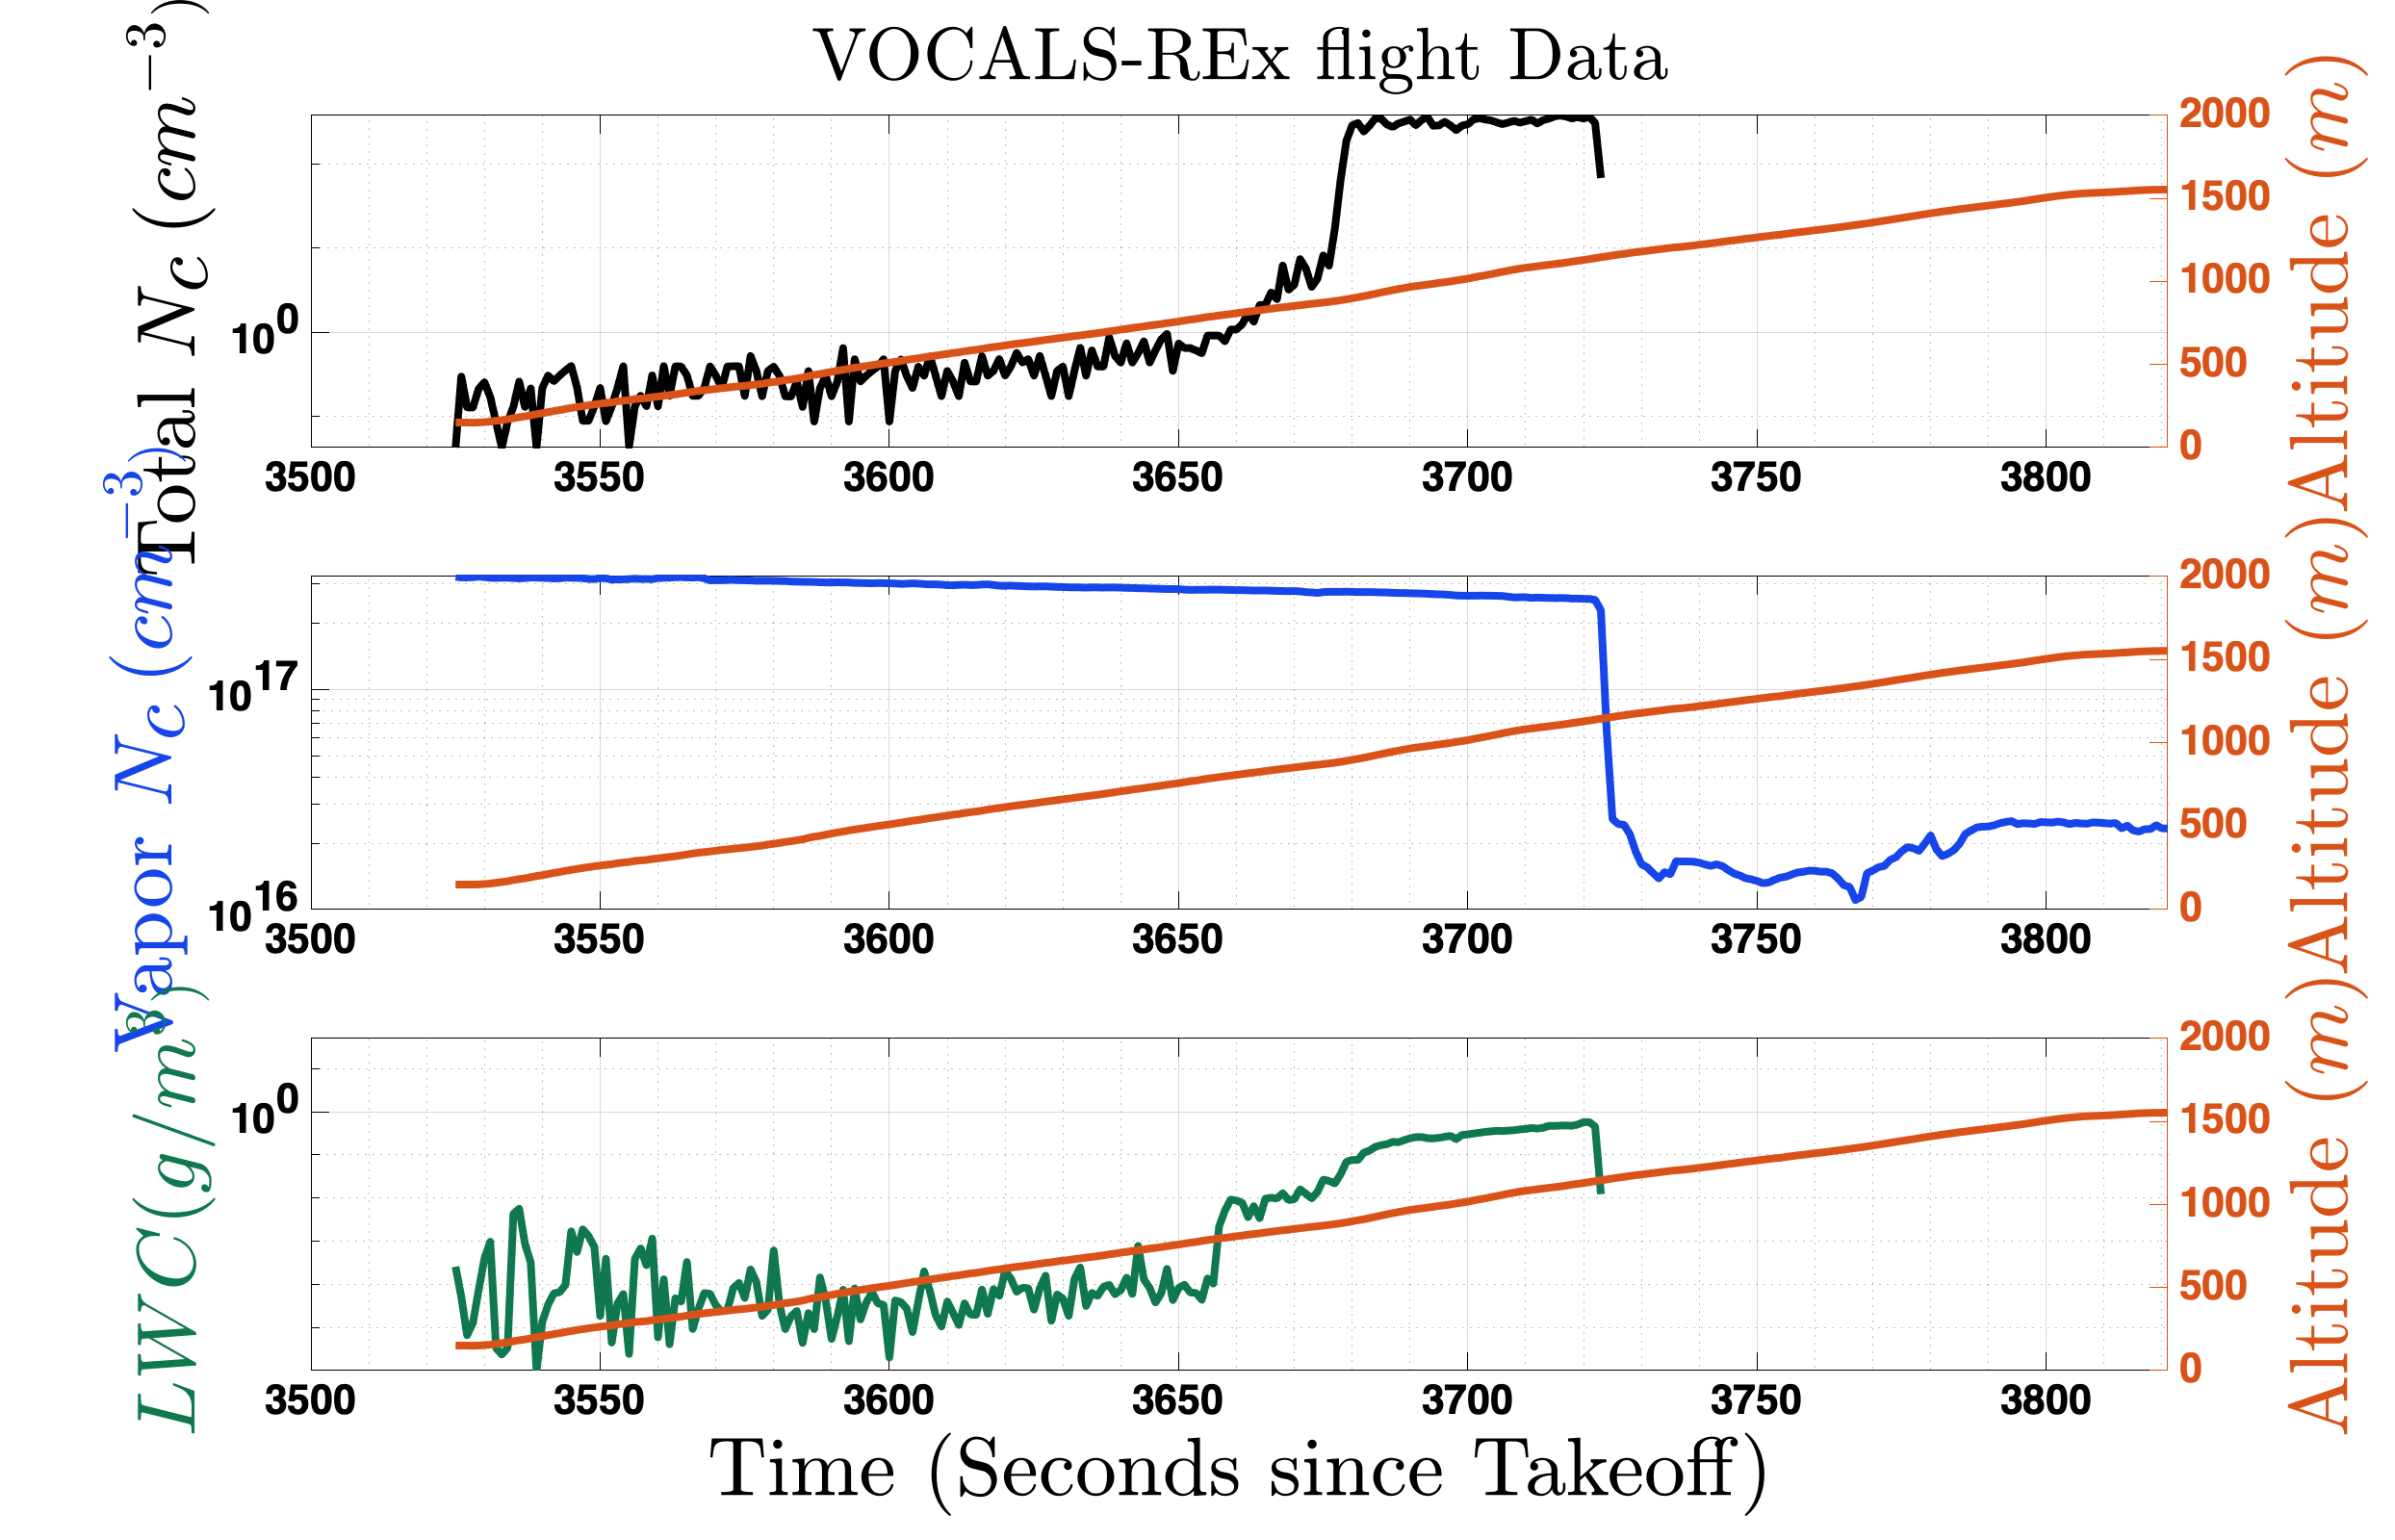

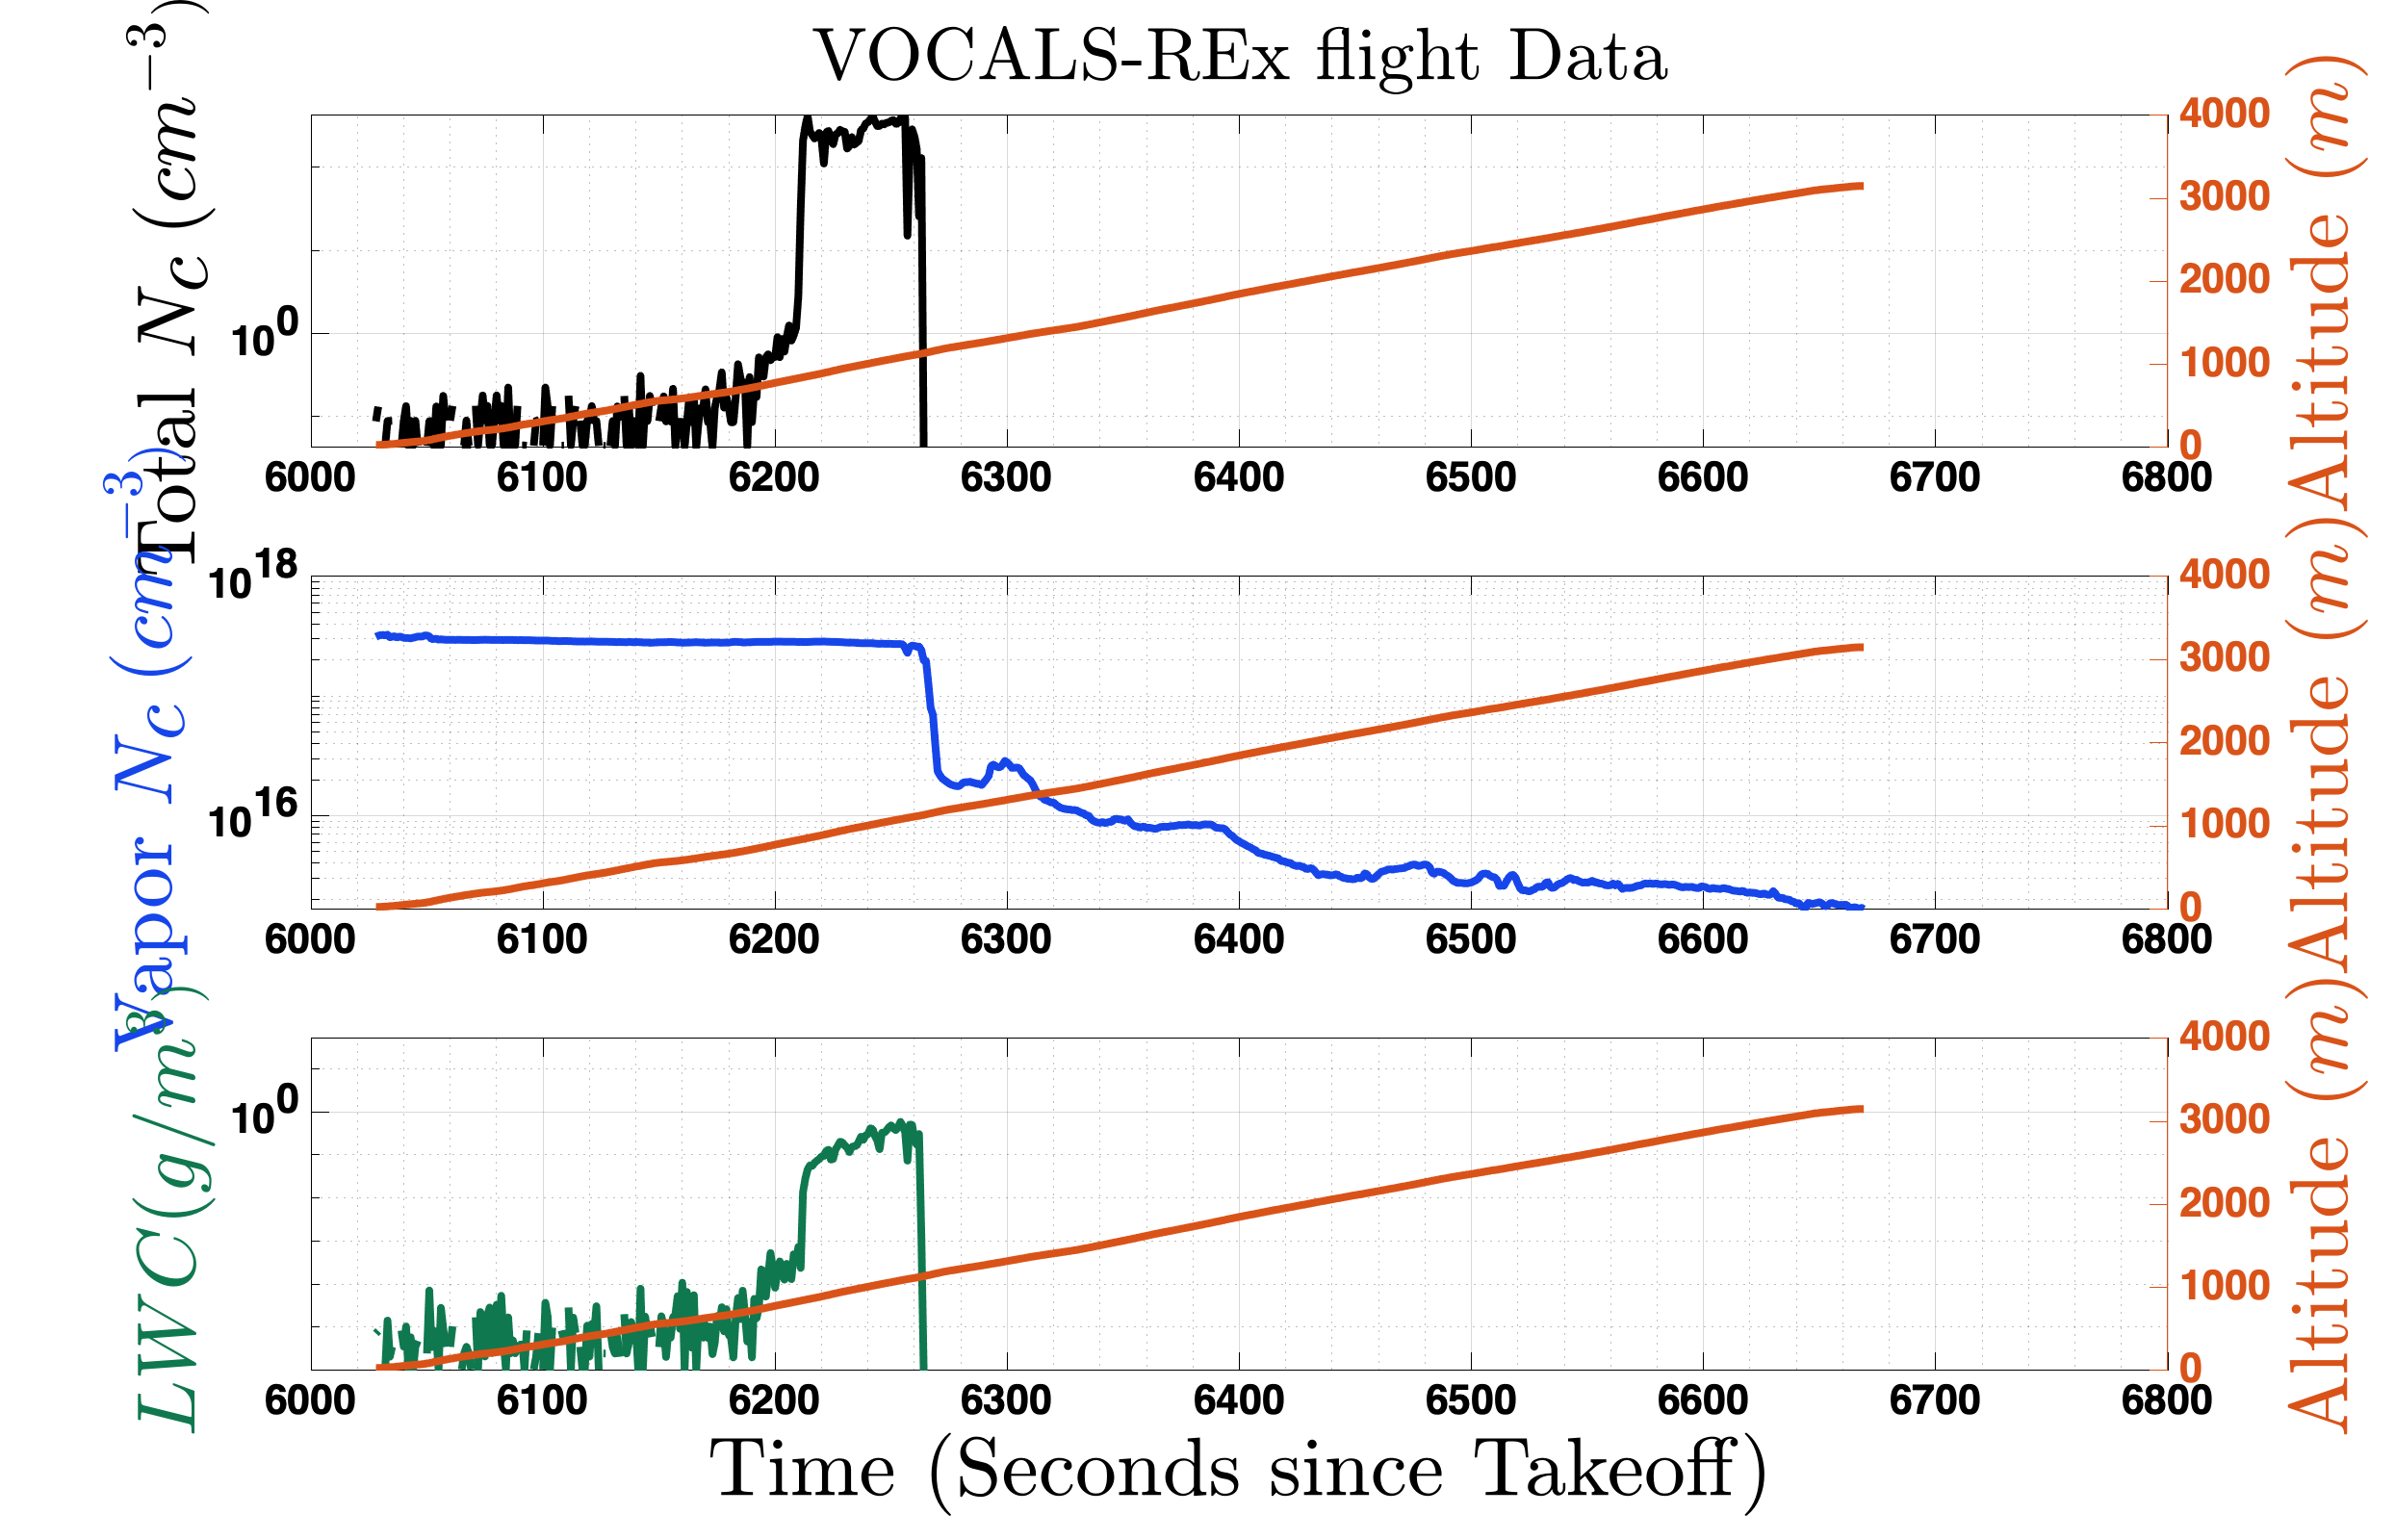

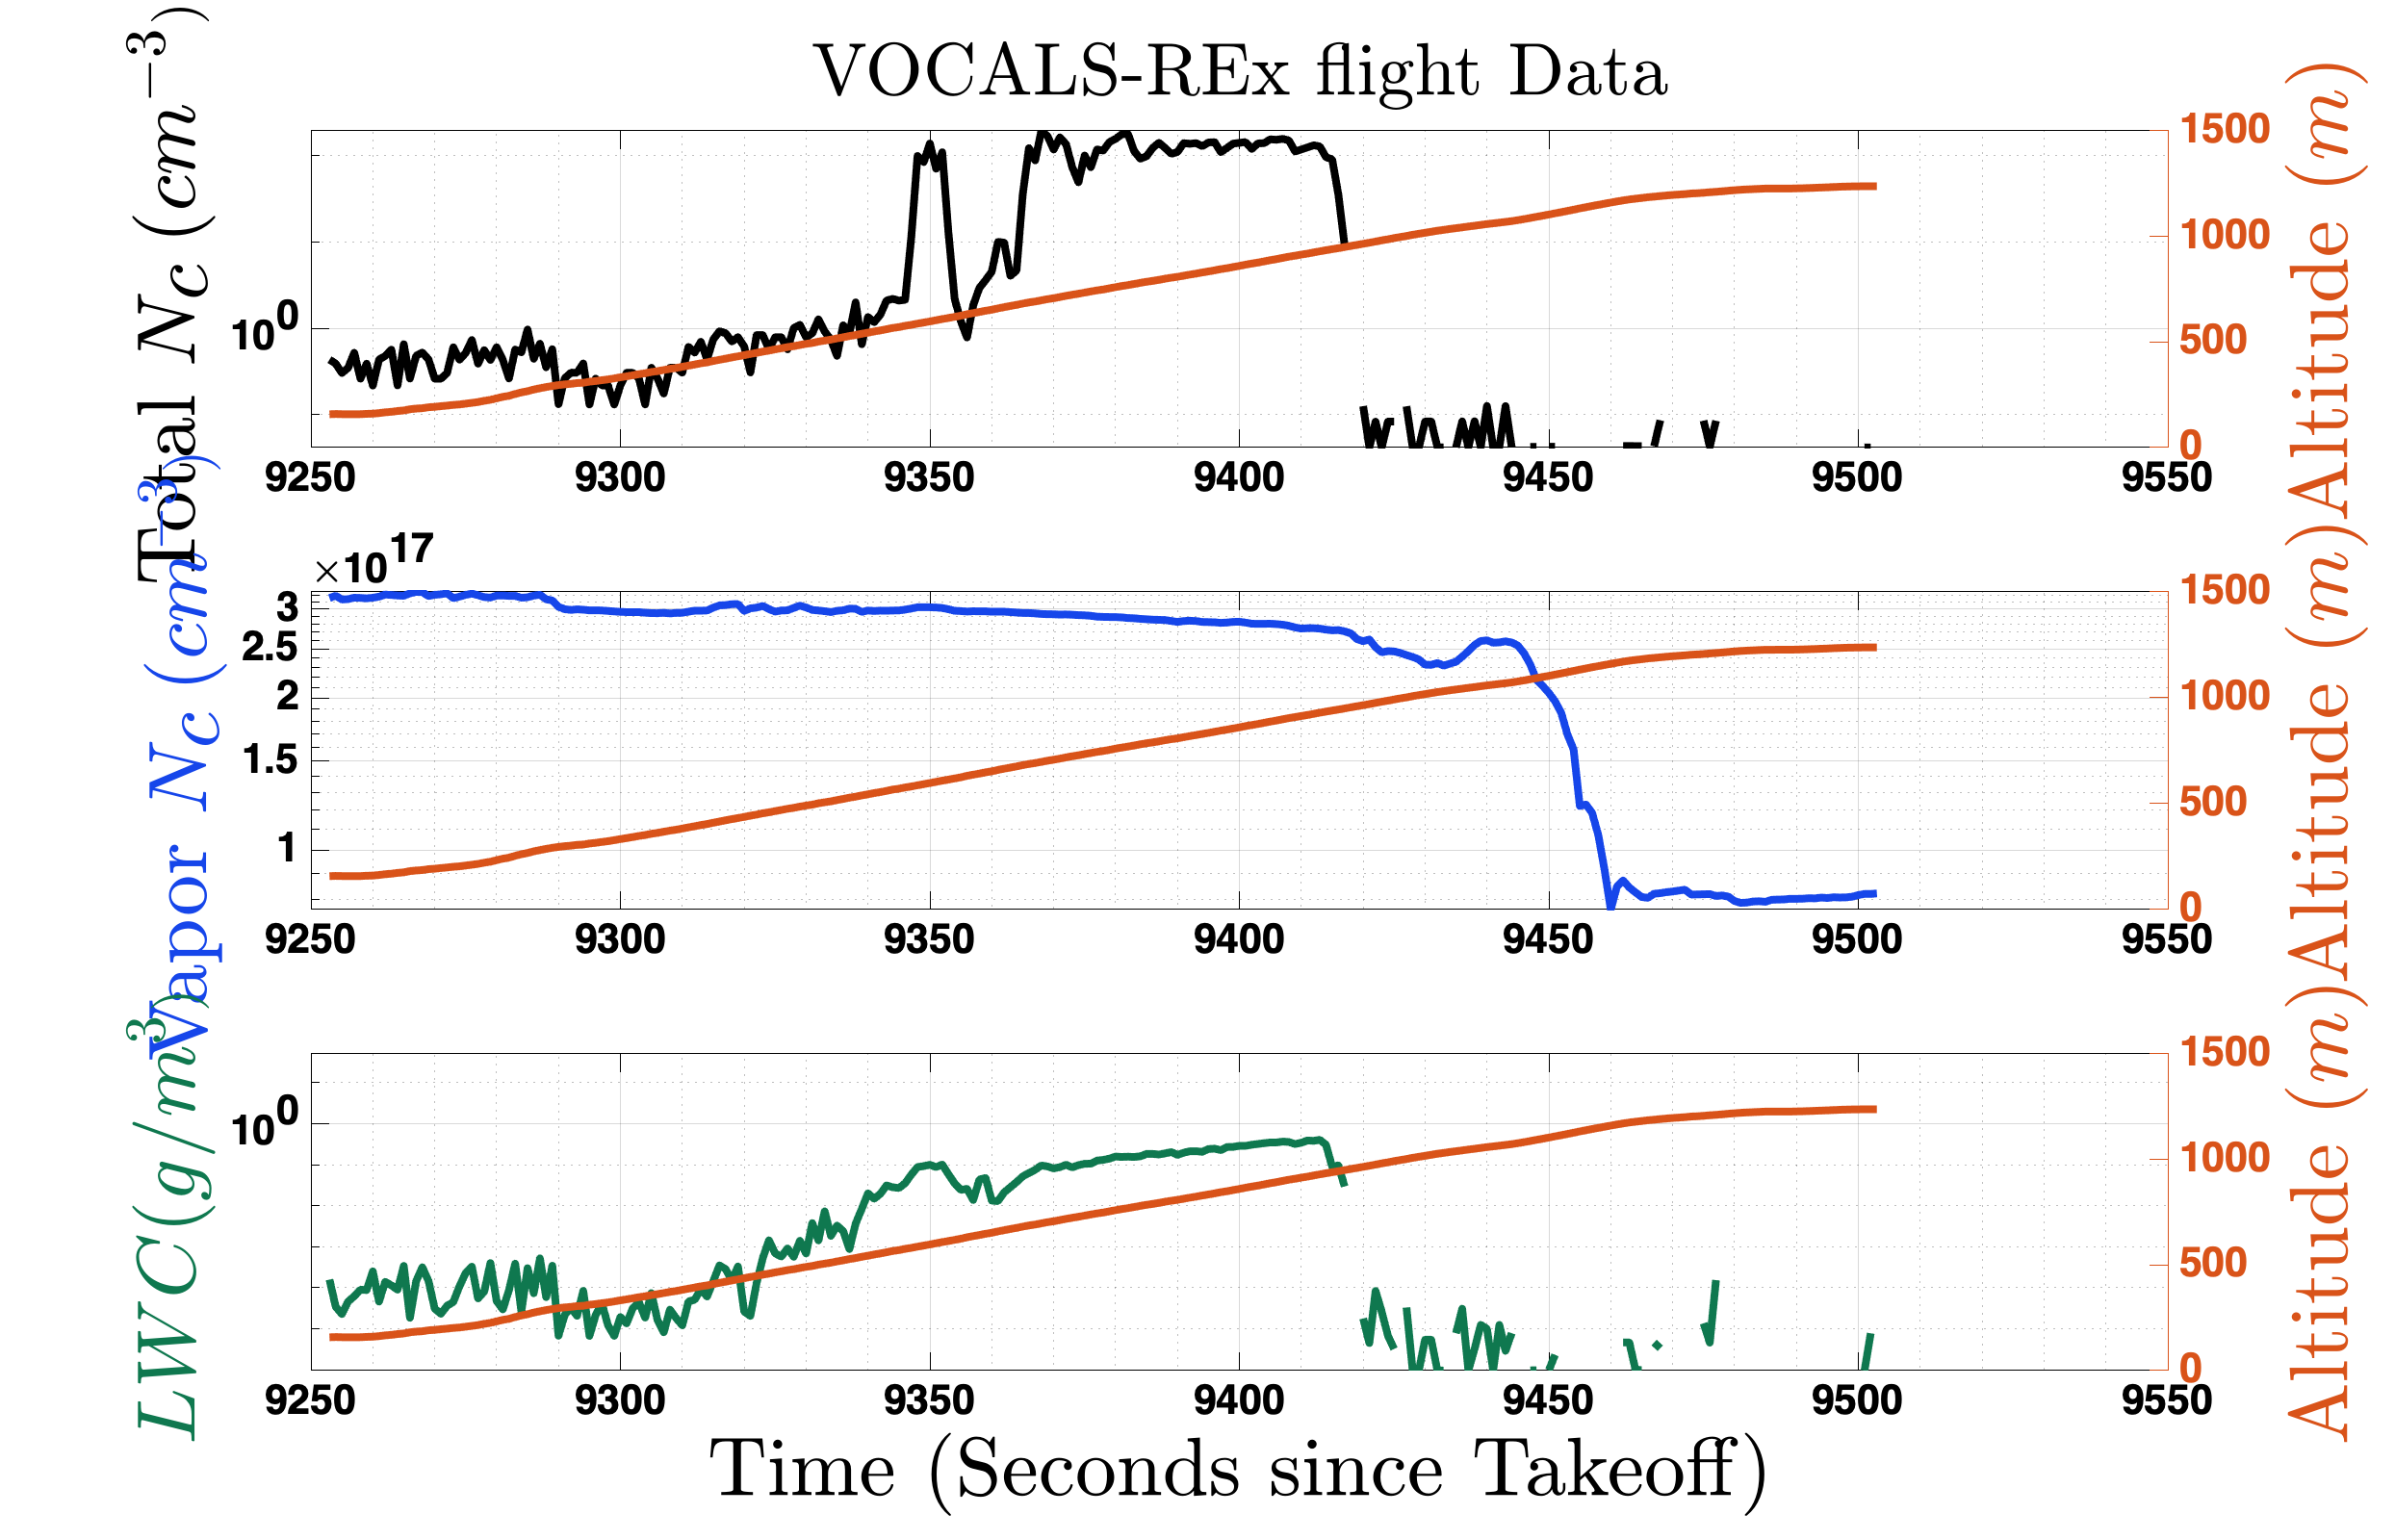

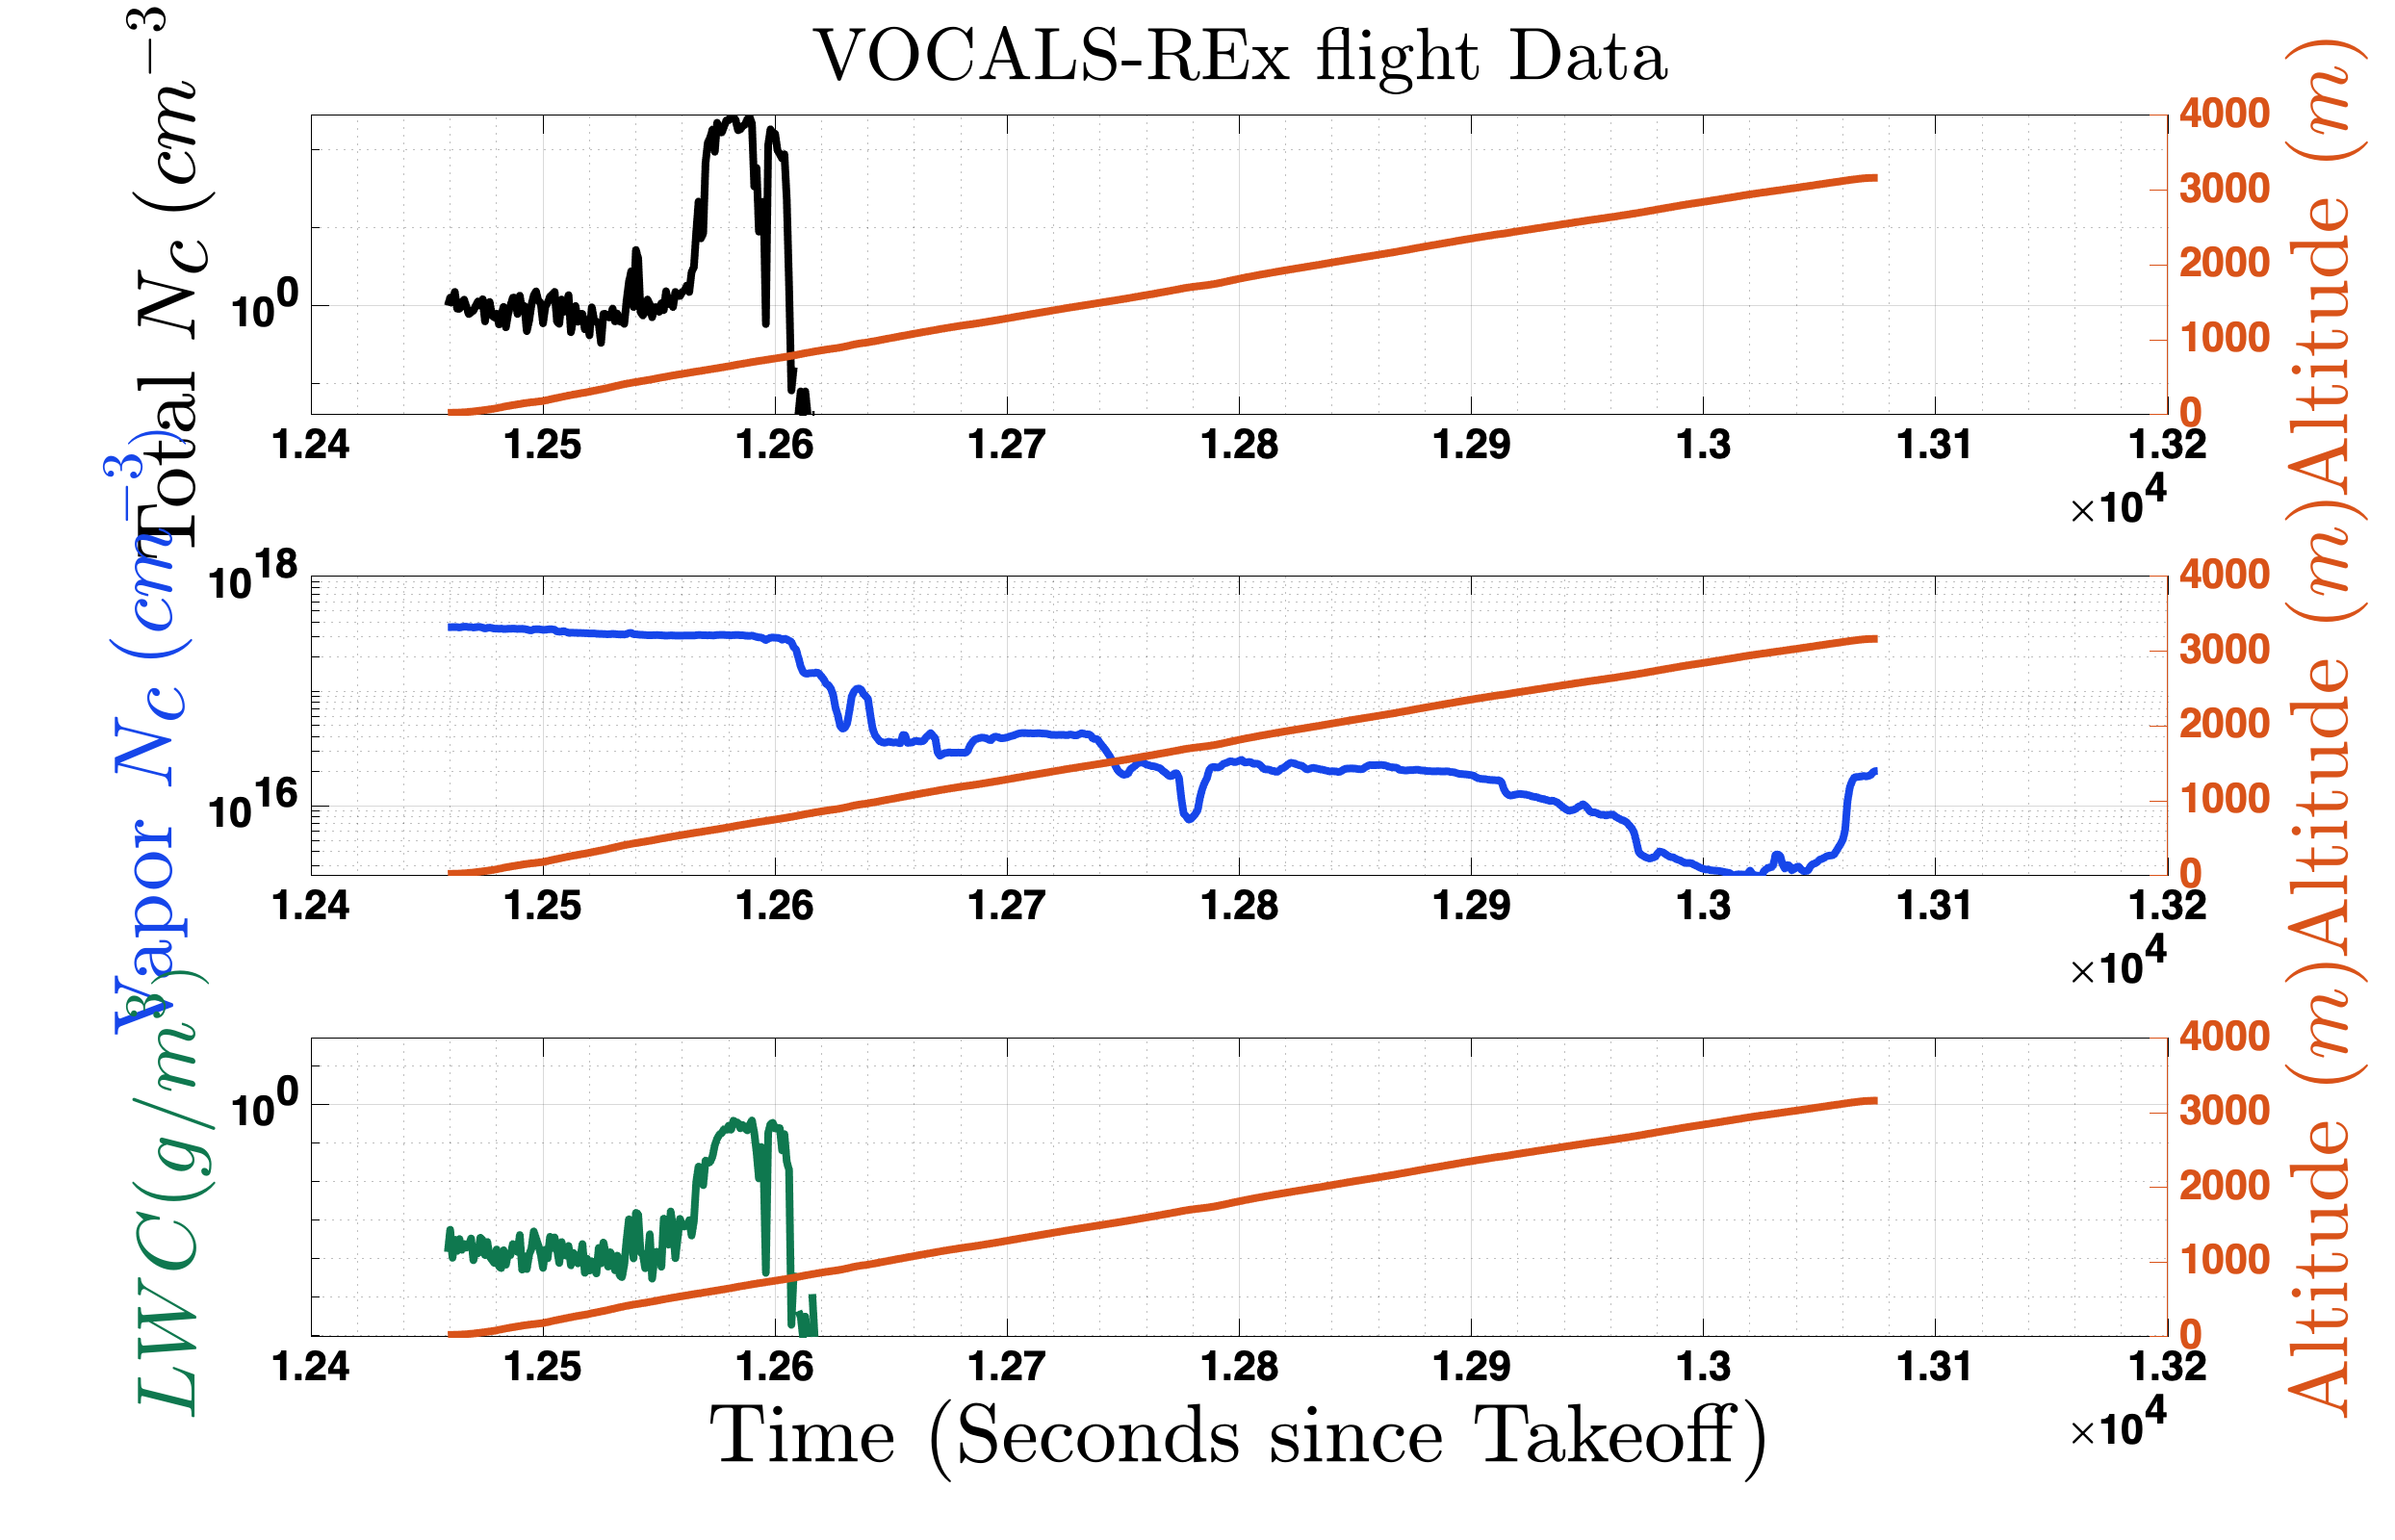

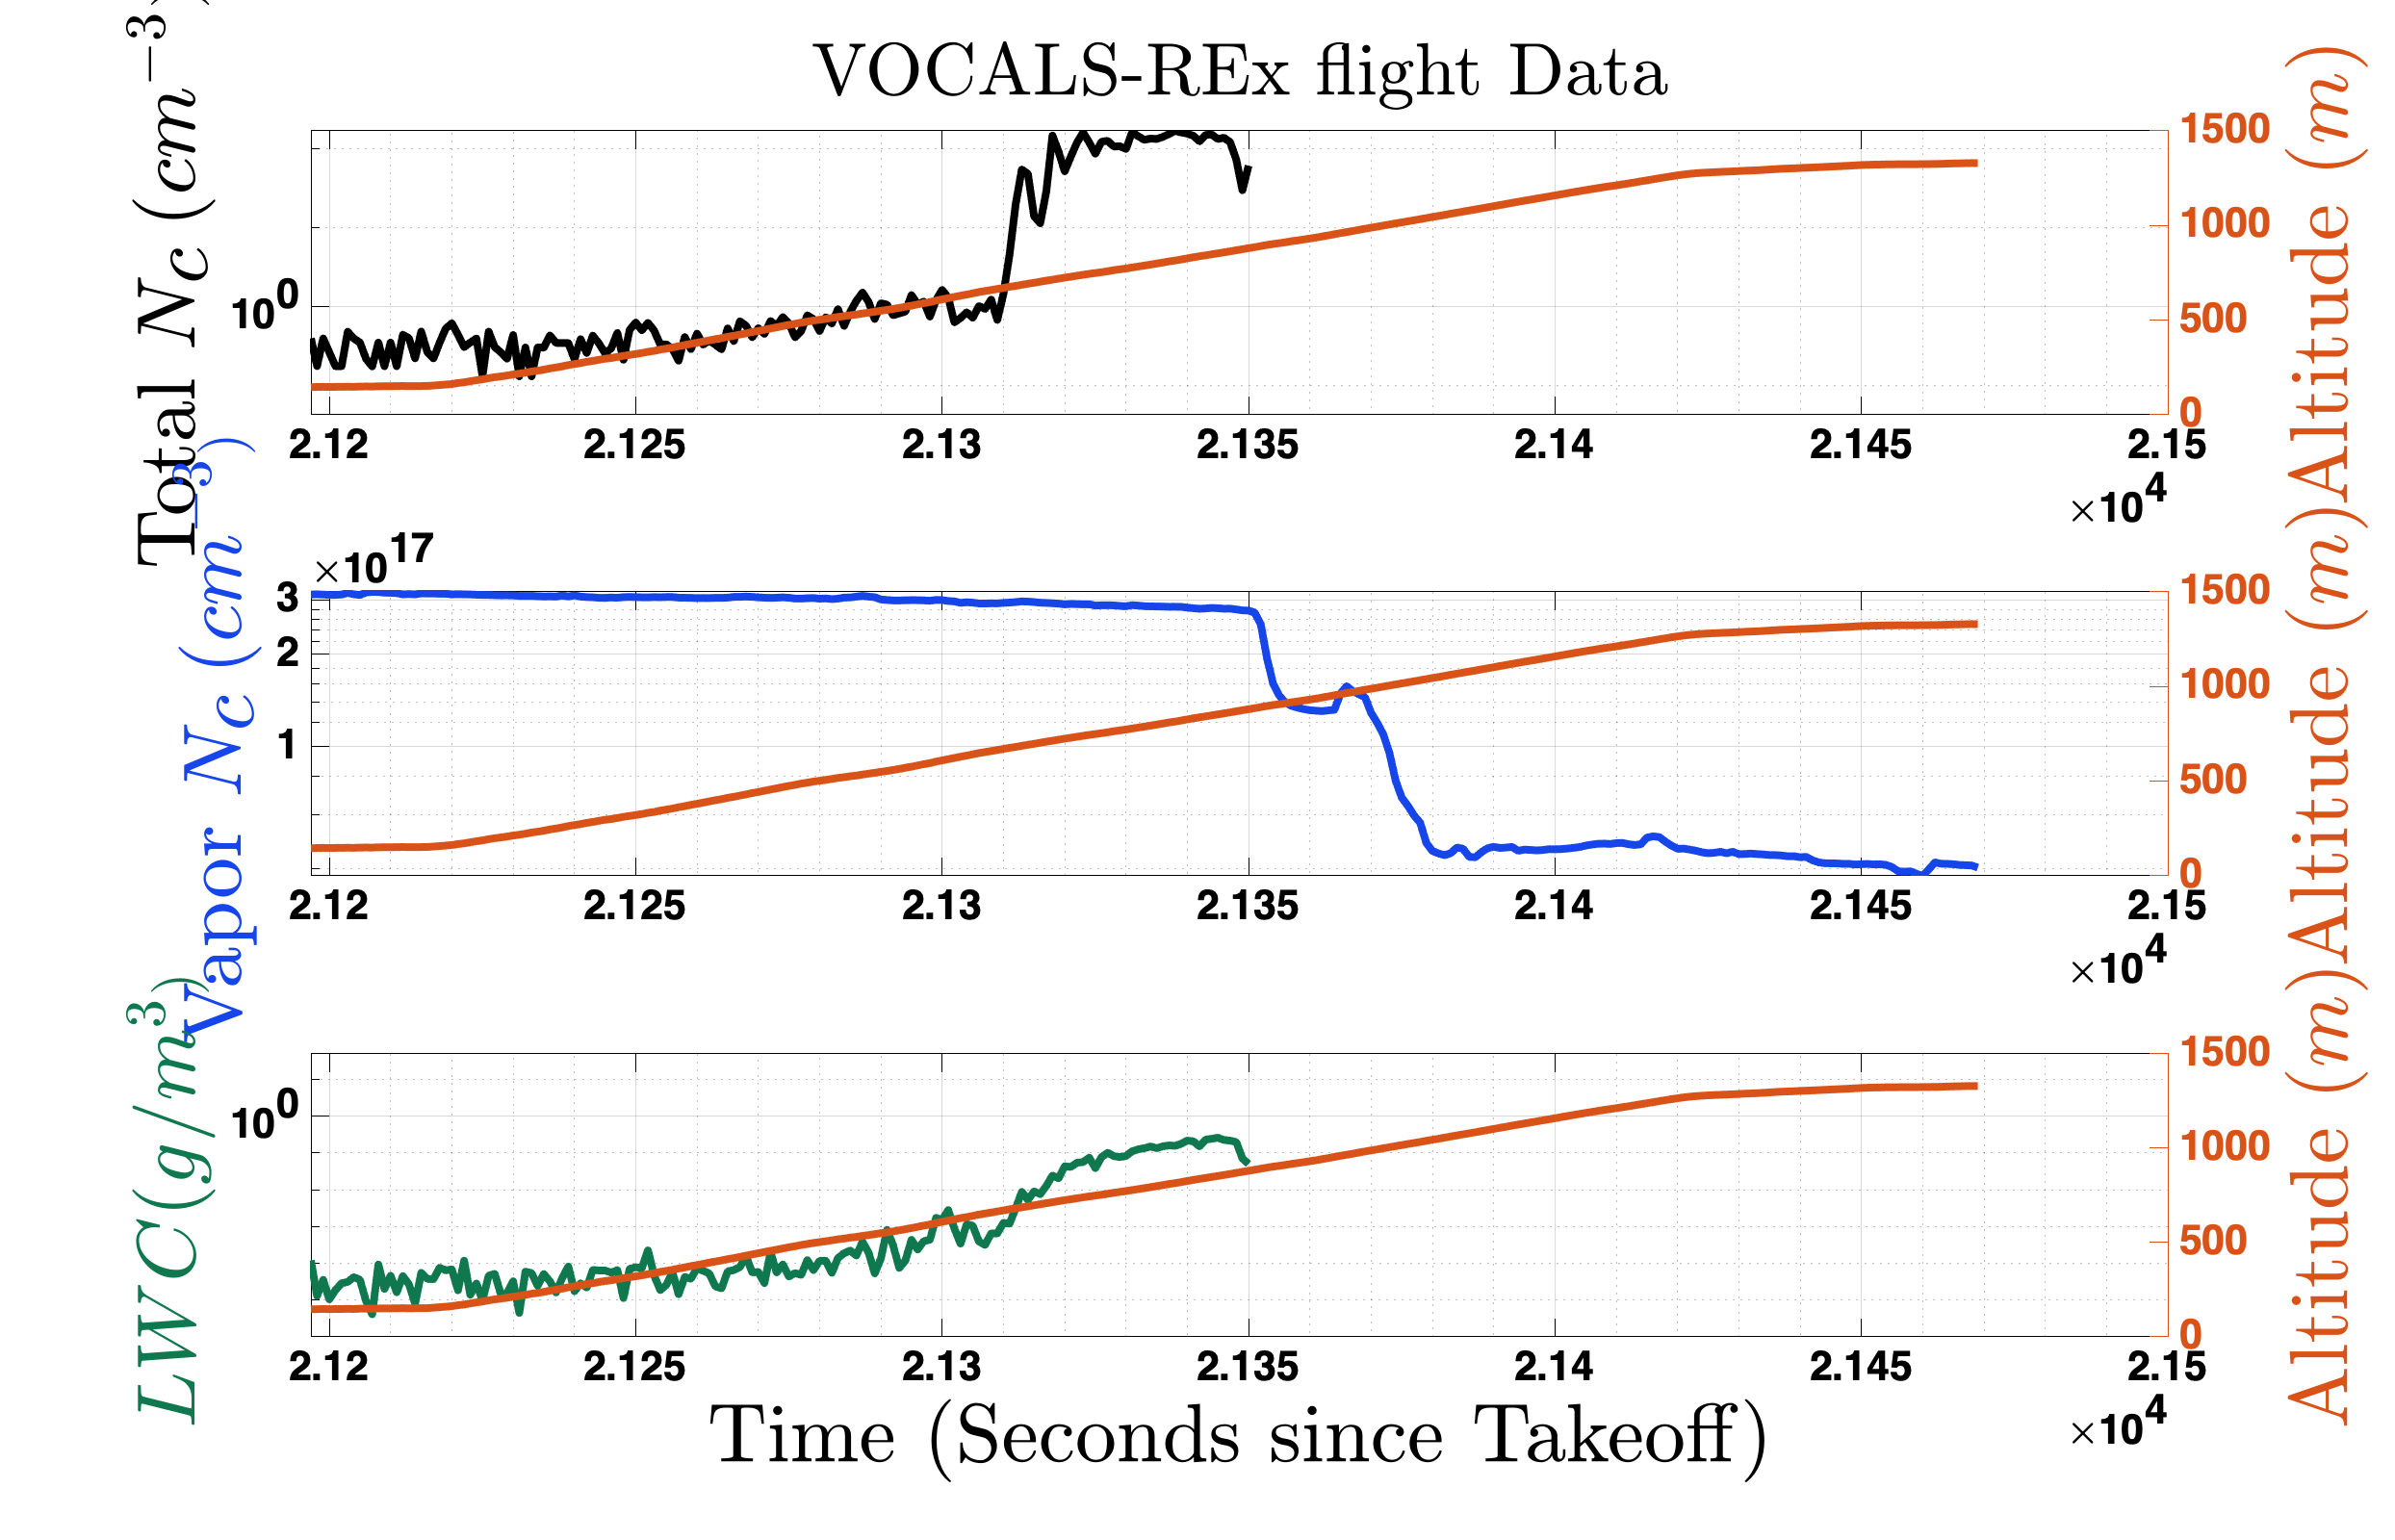

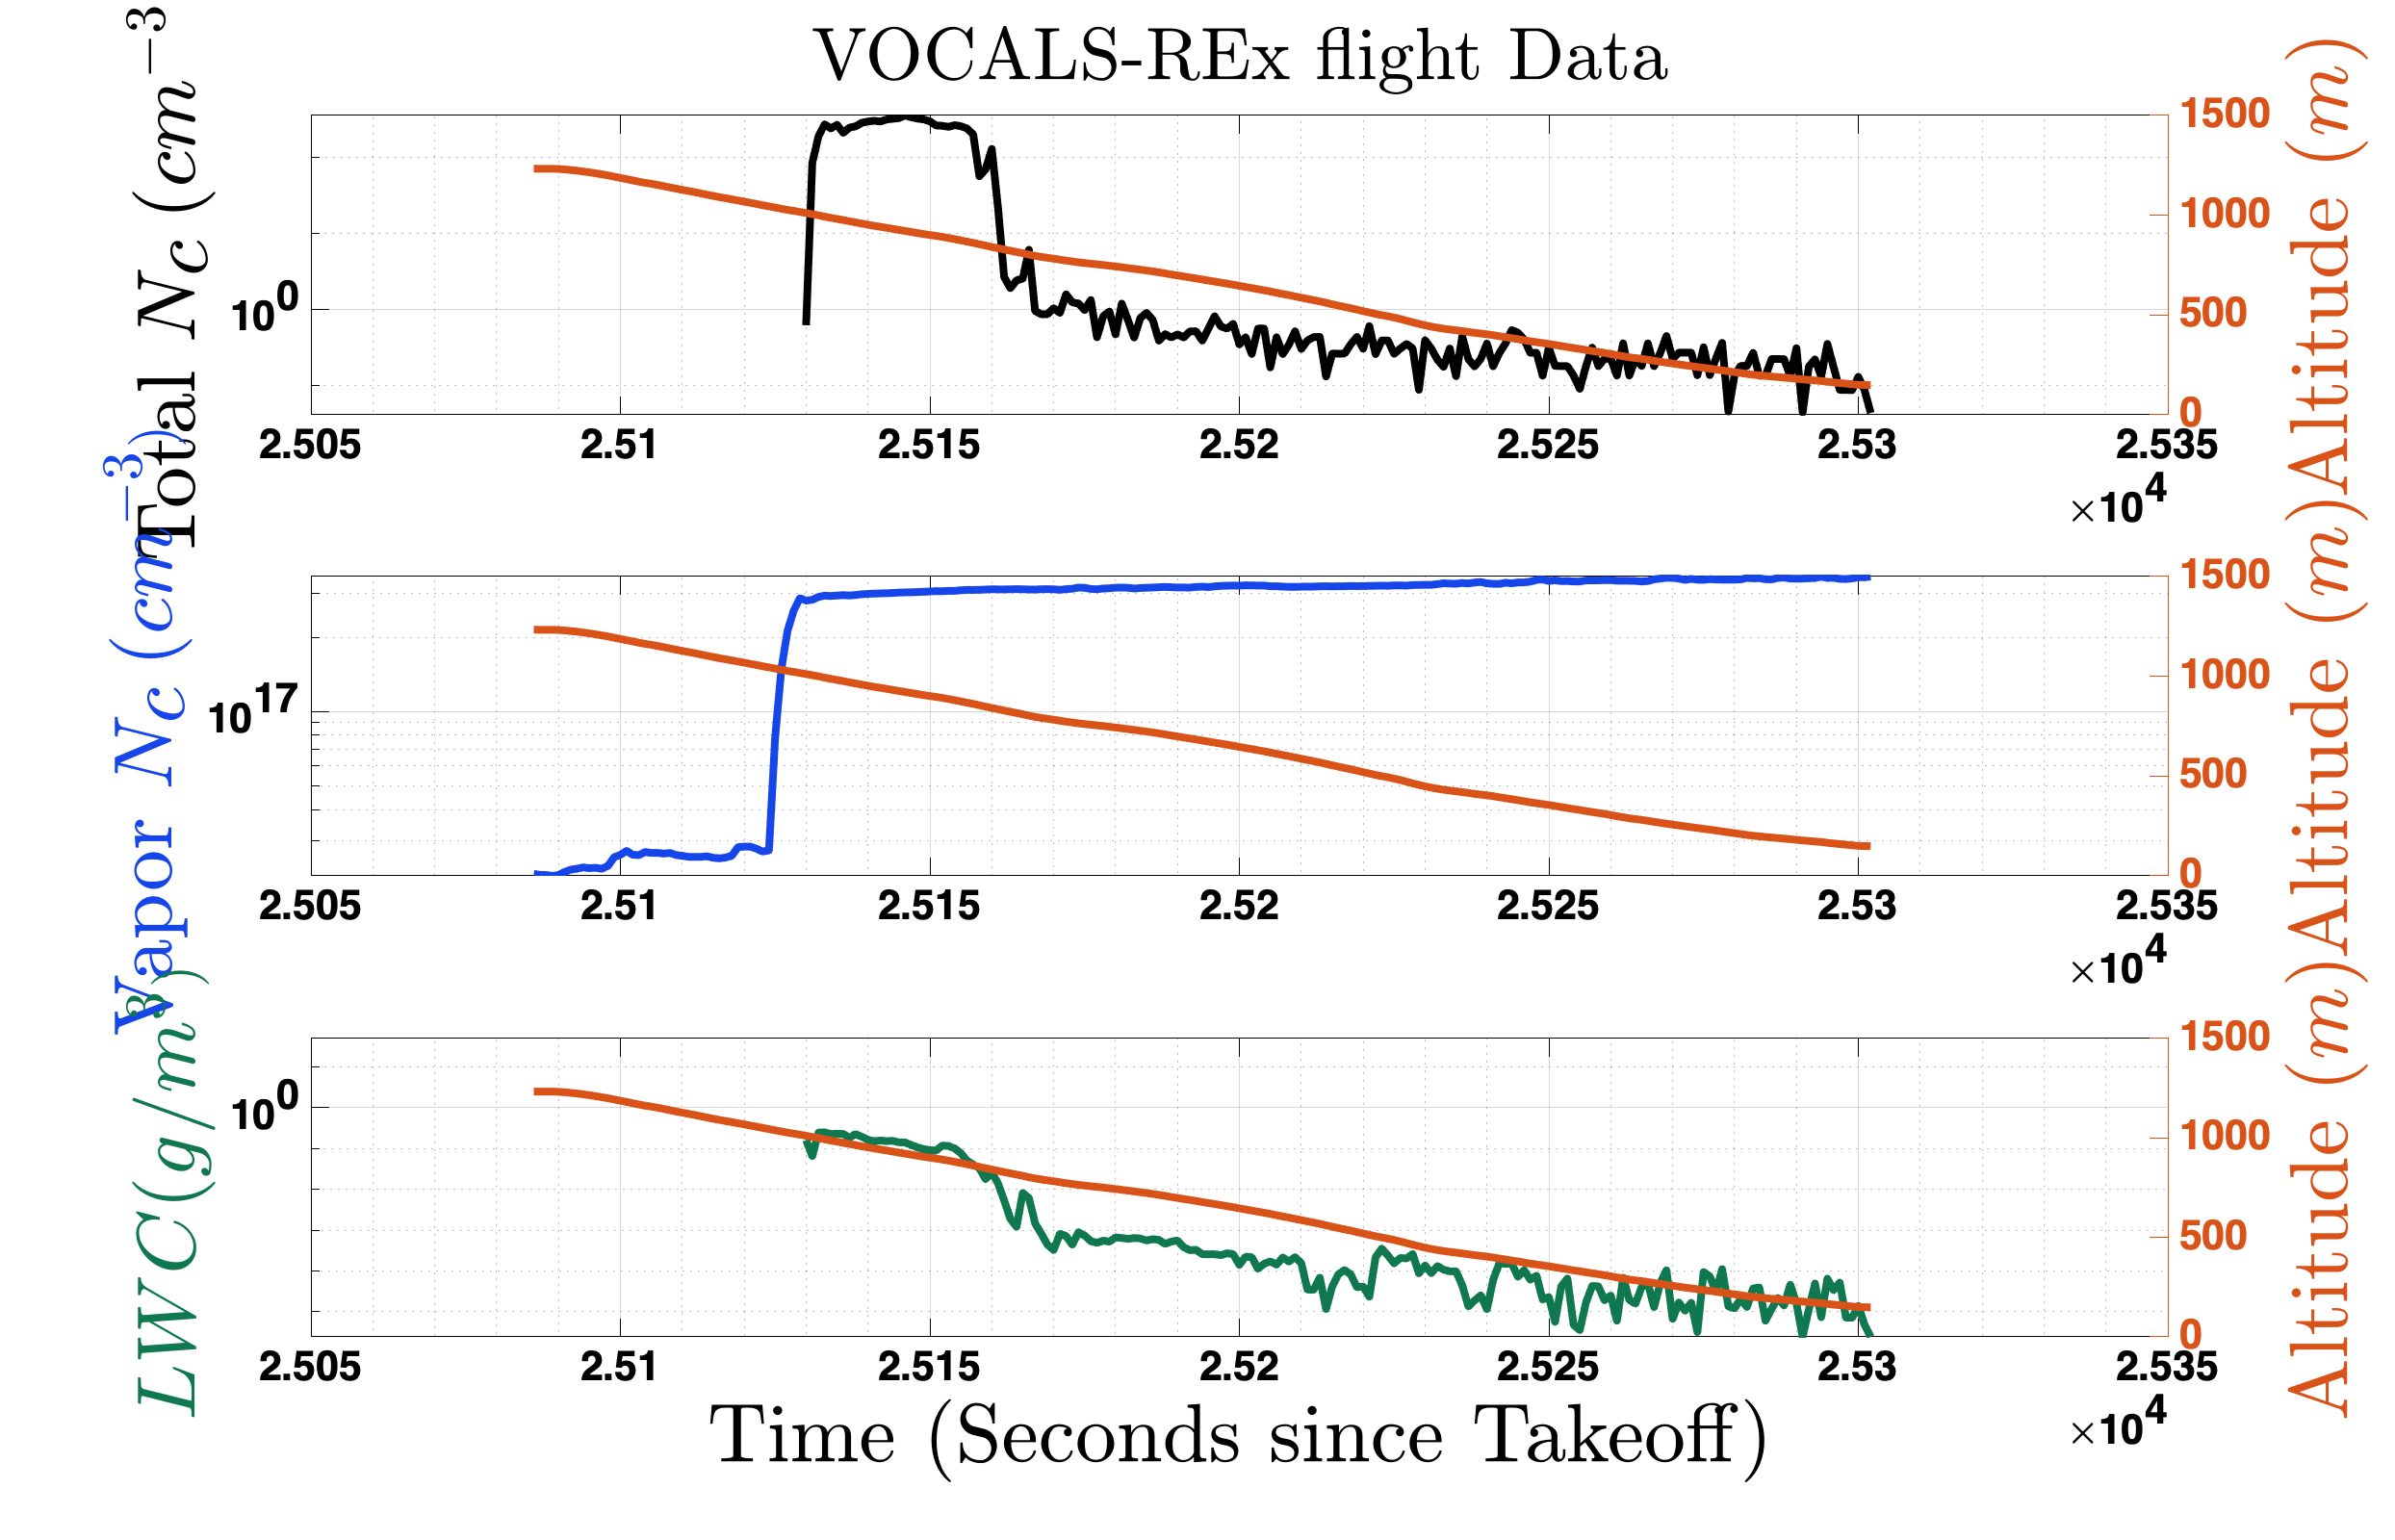

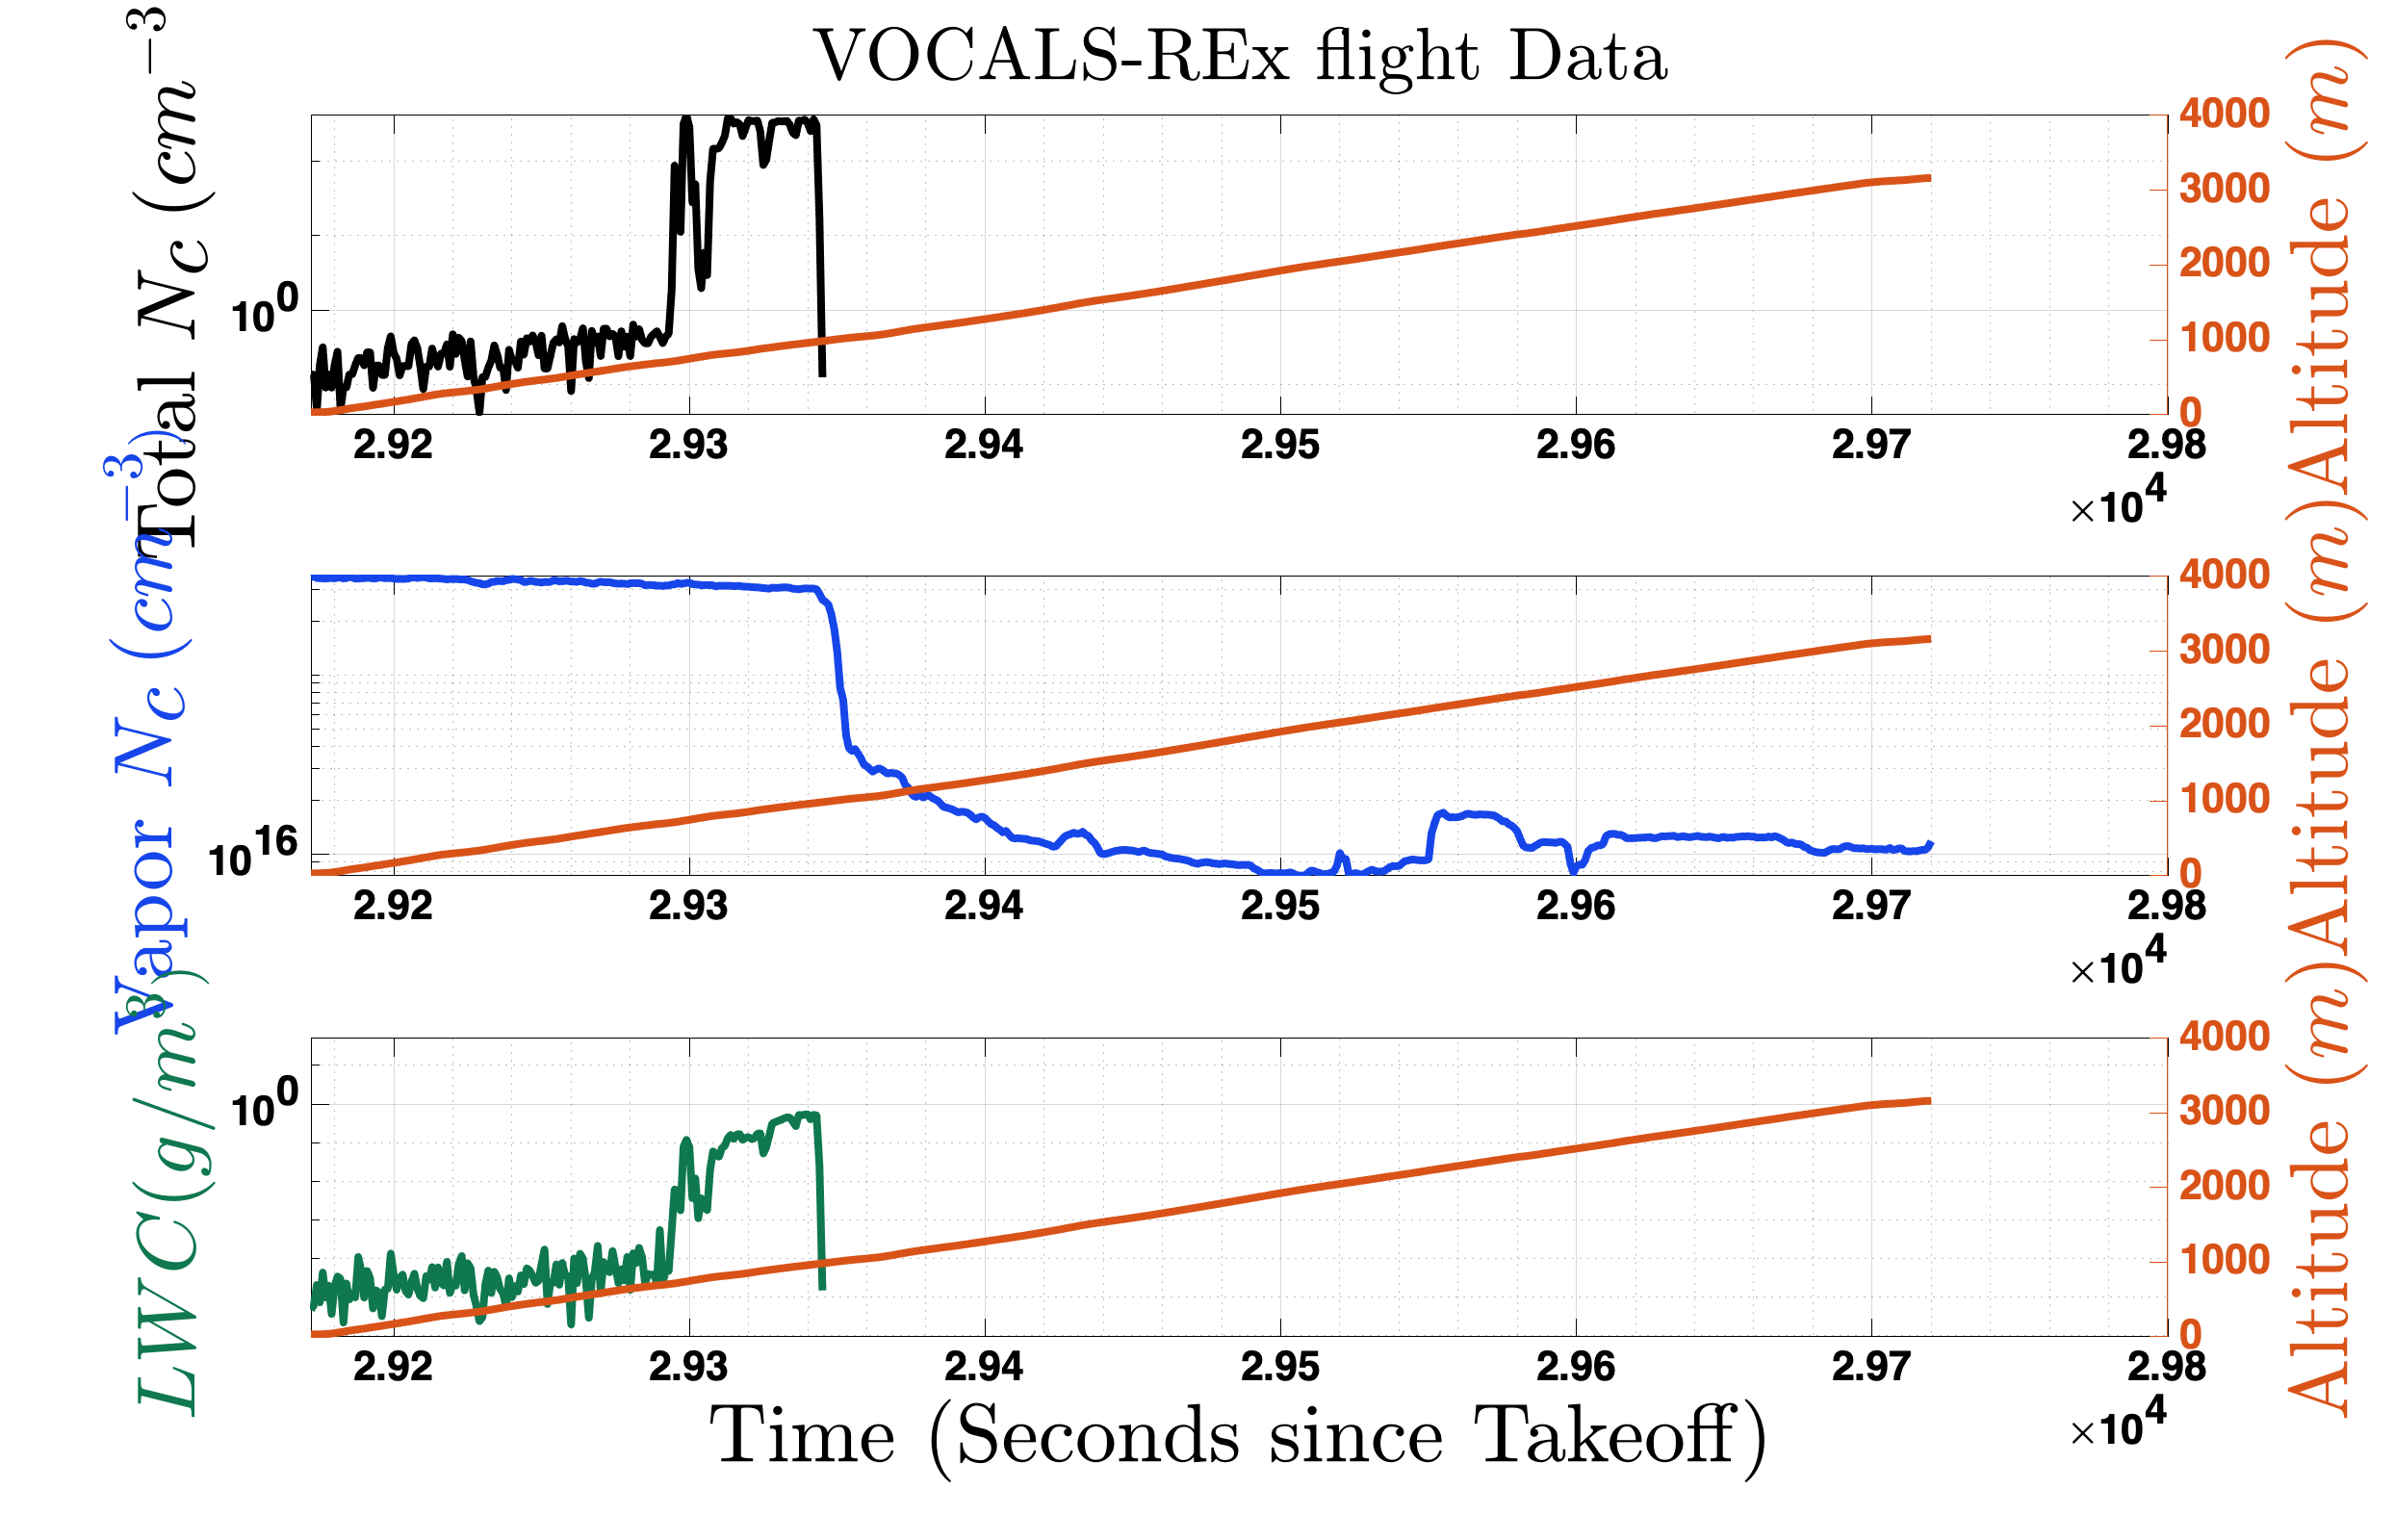


for nn = 1:length(vert_profs_vapor)

    fnt_size_ylabel = 15;

    %  Below this, create a subplot with effective radius versus time and
    %  altitude versus time


    figure; subplot(3,1,1)
    semilogy(double(vert_profs_vapor(nn).time), vert_profs_vapor(nn).total_Nc, 'Color','k');
    grid on; grid minor;
    ylabel('Total $N_c$  $(cm^{-3})$','Interpreter','latex', 'Color','k', 'FontSize', fnt_size_ylabel)
    title('VOCALS-REx flight Data', 'Interpreter','latex')

    hold on;
    yyaxis right;
    plot(double(vert_profs_vapor(nn).time), vert_profs_vapor(nn).altitude)
    ylabel('Altitude ($m$)','Interpreter','latex', 'FontSize', fnt_size_ylabel)

    % grab current axes
    ax1 = gca;

    s2 = subplot(3,1,2);
    semilogy(double(vert_profs_vapor(nn).time), vert_profs_vapor(nn).Nc_vapor_partPres, 'Color', mySavedColors(18, 'fixed'));
    set(s2,'YColor', mySavedColors(18, 'fixed'));
    grid on; grid minor;
    %ylim([0, 50])           % no need to look at effective radii larger than 50 microns

    hold on;
    yyaxis right;
    plot(double(vert_profs_vapor(nn).time), vert_profs_vapor(nn).altitude)
    ylabel('Altitude ($m$)','Interpreter','latex', 'FontSize', fnt_size_ylabel)

    % change color of left y axis
    yyaxis left
    ylabel('Vapor $N_c$ $(cm^{-3})$','Interpreter','latex', 'Color',mySavedColors(18, 'fixed'), 'FontSize',fnt_size_ylabel)


    % grab current axes
    ax2 = gca;


    s3 = subplot(3,1,3);
    semilogy(double(vert_profs_vapor(nn).time), vert_profs_vapor(nn).lwc, 'Color', mySavedColors(15, 'fixed'));
    set(s3,'YColor', mySavedColors(15, 'fixed'));
    grid on; grid minor;
    xlabel('Time (Seconds since Takeoff)','Interpreter','latex')
    ylim([0, 50])           % no need to look at effective radii larger than 50 microns

    hold on;
    yyaxis right;
    plot(double(vert_profs_vapor(nn).time), vert_profs_vapor(nn).altitude)
    ylabel('Altitude ($m$)','Interpreter','latex', 'FontSize',fnt_size_ylabel)

    % change color of left y axis
    yyaxis left
    ylabel('$LWC (g/m^3)$','Interpreter','latex', 'Color',mySavedColors(15, 'fixed'), 'FontSize', fnt_size_ylabel)


    % grab current axes
    ax3 = gca;

    linkaxes([ax1 ax2 ax3],'x');


    set(gcf, 'Position',[0 0 1400, 900])

end

## Let's look at each vapor profile as a function of height

Highlight the segment of the profile that is defined as cloud using the LWC and Nc thresholds above

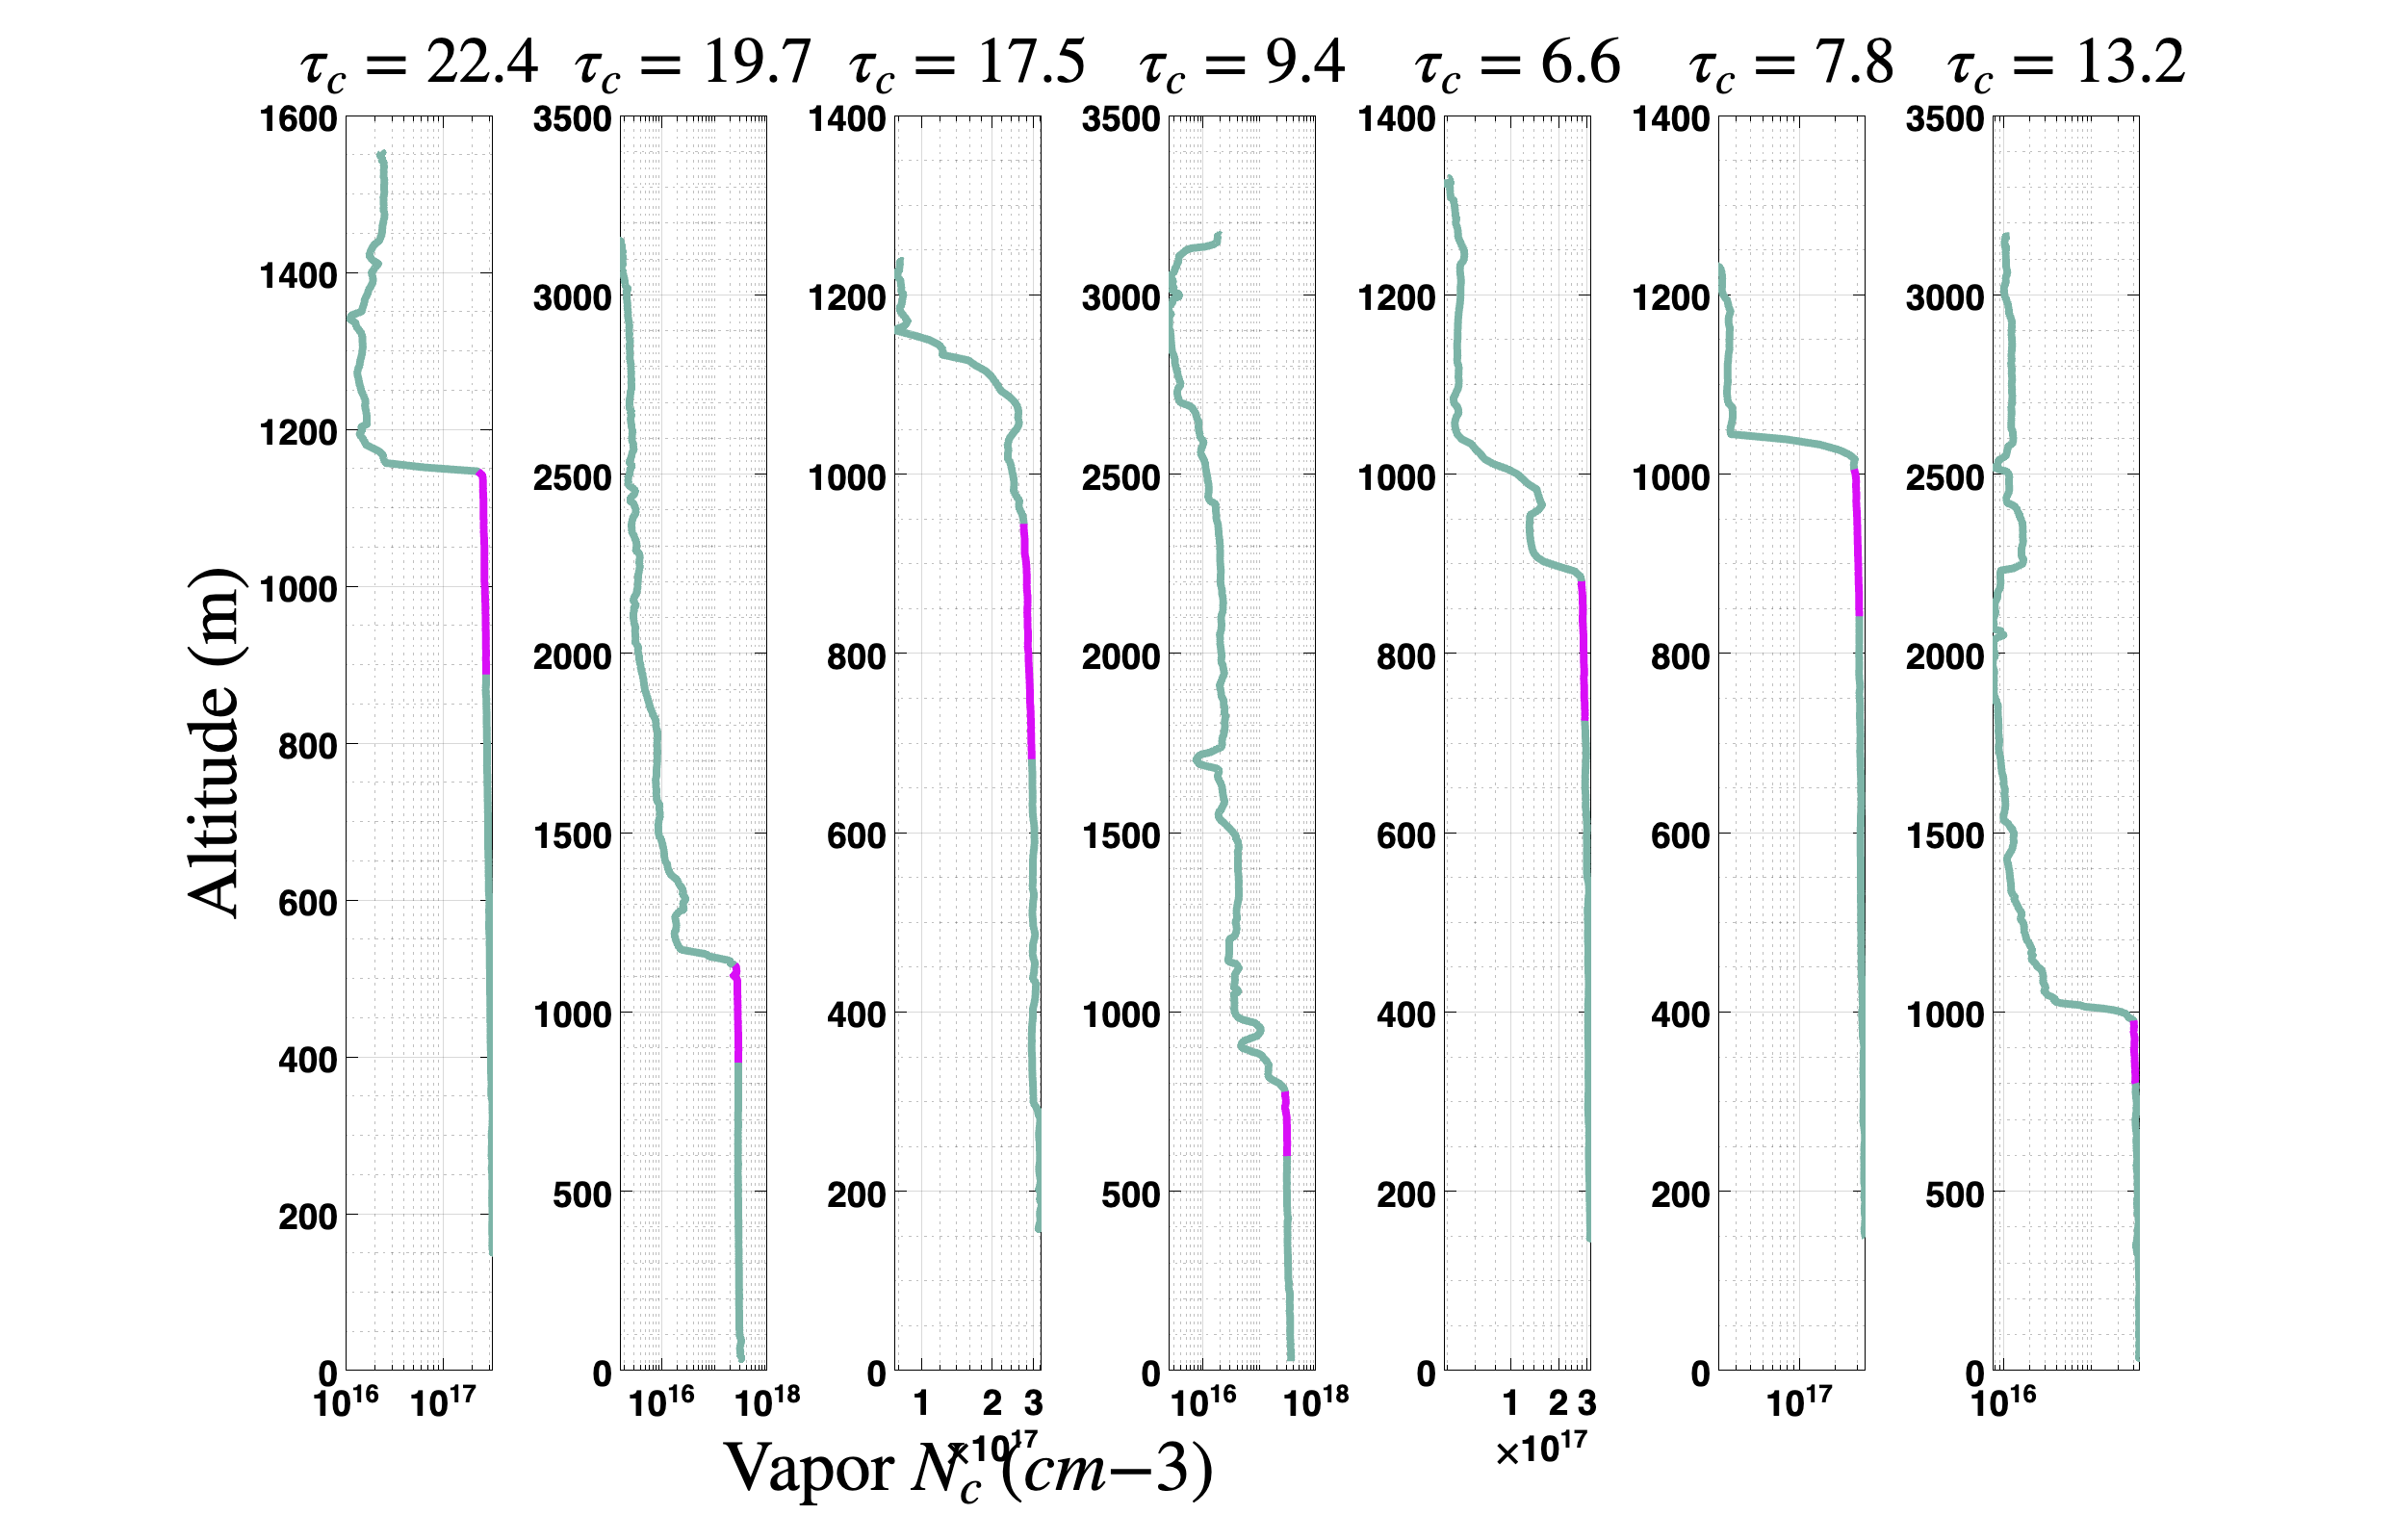

figure;

for nn = 1:length(vert_profs_vapor)

    subplot(1,length(vert_profs_vapor),nn)
    semilogx(vert_profs_vapor(nn).Nc_vapor_partPres, vert_profs_vapor(nn).altitude,...
        'Color', mySavedColors(2,'fixed'))
    grid on; grid minor

    hold on

    % color the vertical segment pertaining to the cloud location 
    semilogx(vert_profs_vapor(nn).Nc_vapor_partPres(vert_profs_vapor(nn).cloud_idx(1):...
        vert_profs_vapor(nn).cloud_idx(2)), vert_profs_vapor(nn).altitude(vert_profs_vapor(nn).cloud_idx(1):...
        vert_profs_vapor(nn).cloud_idx(2)), 'Color', mySavedColors(1,'fixed'))

    if nn==1
        ylabel('Altitude (m)', 'FontSize', 25, 'Interpreter','latex')

    elseif nn==floor(length(vert_profs_vapor)/2)
        xlabel('Vapor $N_c$ ($cm{-3}$)', 'Interpreter','latex', 'FontSize',25)

    end

    title(['$\tau_c = $', num2str(round(vert_profs_vapor(nn).cloud_optical_depth,1))], ...
        'FontSize', 21, 'Interpreter','latex')


end

set(gcf, 'Position',[0 0 1400, 900])